tic
%PreLab question 1: Discrete open loop transfer function
close all;
clear all;
clc;

% Machine Parameters
ka=0.887;                       % Sg: Motor amplifier constant [A/V]
kt=0.72;                        % Motor torque constant [Nm/A]
Je=7e-4;                        % Equivalent Inertia [kgm^2]
Be=0.00612;                     % Equivalent Damping [Nm/rad/s]
hp=20;                          % Ball screw pitch [mm]
ke=hp/2/pi;                     % Encoder gain
Ts=0.0002;                      % Sampling interval [s]
p1=Be/Je;                       % Pole of 1st order system approximation

%  Constants so matlab runs properly
num_LL=[1 1];
den_LL=[1 1];
C=tf(num_LL, den_LL);
num_I=[1 1];
den_I=[1 1];
I=tf(num_I, den_I);
LL_d=c2d(C,Ts,"tustin");
I_d=c2d(I,Ts,"tustin");

[LL_d_num, LL_d_den] = tfdata(LL_d, 'v');
[I_d_num, I_d_den] = tfdata(I_d, 'v');


%PFD Simplifying Constants
A1=-Je/Be^2;        
A2=1/Be;
C=Je/Be^2;
K1=ka*kt*ke;                    % Simplifying constant
alpha_0=K1*(A1+C)

alpha_0 = 0

alpha_1=K1*(-A1*(1+exp(-p1*Ts)) + A2*Ts-2*C)

alpha_1 = 5.8048e-05

alpha_2=K1*(A1*exp(-p1*Ts)-A2*Ts*exp(-p1*Ts)+C)

alpha_2 = 5.8014e-05

beta_1=-(1+exp(-p1*Ts))

beta_1 = -1.9983

beta_2=exp(-p1*Ts)

beta_2 = 0.9983

    
num=[0 K1];
den=[Je Be 0];
Gp_ol_s=tf(num,den);                  % Open loop plant transfer function in s domain

Gp_ol_z=c2d(Gp_ol_s,Ts)                  % Open loop plant transfer function in z domain

Gp_ol_z =
 
  5.805e-05 z + 5.801e-05
  -----------------------
  z^2 - 1.998 z + 0.9983
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


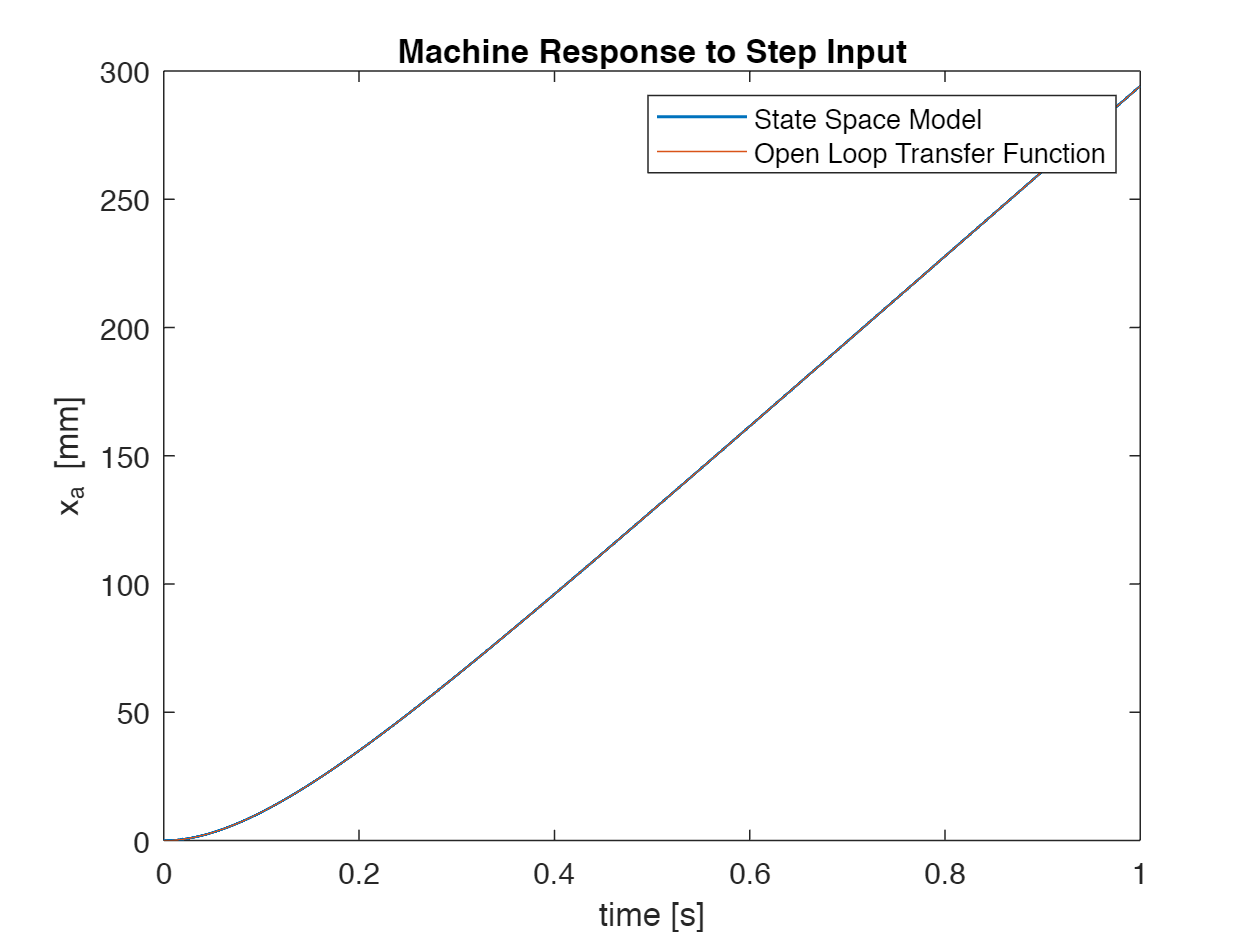

% Pre-lab Question 2

% Open loop Discrete State Space
PHI_ol = [1-Be*Ts/Je 0 ; ke*Ts 1];
H_ol = [Ts-Be*Ts^2/2/Je 0; ke*Ts^2/2 Ts]*[ka*kt/Je 0; 0 0];

C = [0 1];
D = [0 0];

sys_d1 = ss(PHI_ol,H_ol,C,D,Ts);                % Don't forget the sampling Time

[x_a_discrete,t]= step(sys_d1,1);
figure(2); 
plot(t,x_a_discrete(:,1,1),'linewidth',1) % Only plot output xa as the result of input xr
hold on; 
xlabel('time [s]'); 
ylabel('x_a [mm]');
title("Machine Response to Step Input");
[y_d2, t]=step(Gp_ol_z,1);
plot(t,y_d2(:,1,1));
legend("State Space Model", "Open Loop Transfer Function");
hold off;

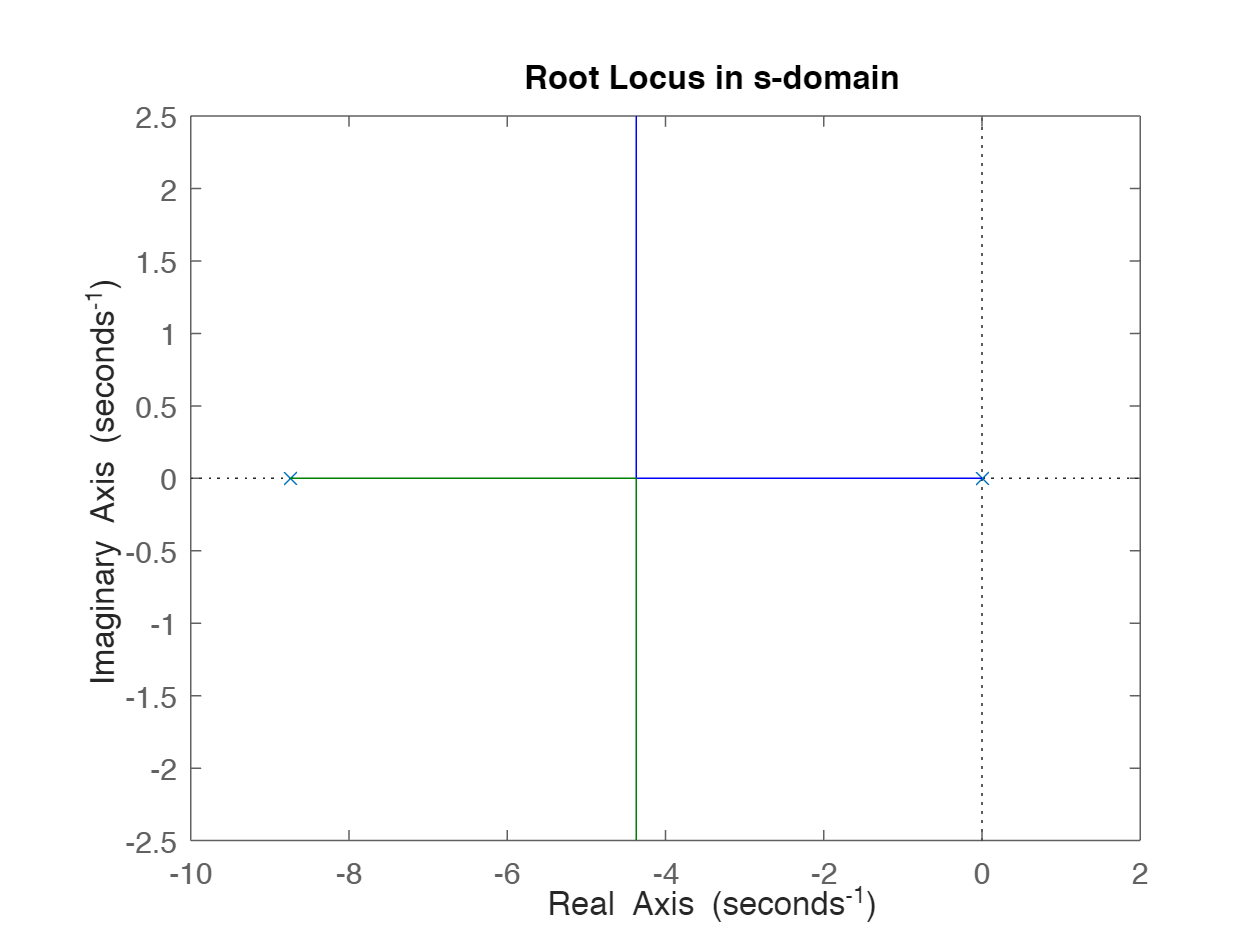

% Prelab Question 3

%Plot Root Locus in s domain
rlocus(Gp_ol_s);
title("Root Locus in s-domain");

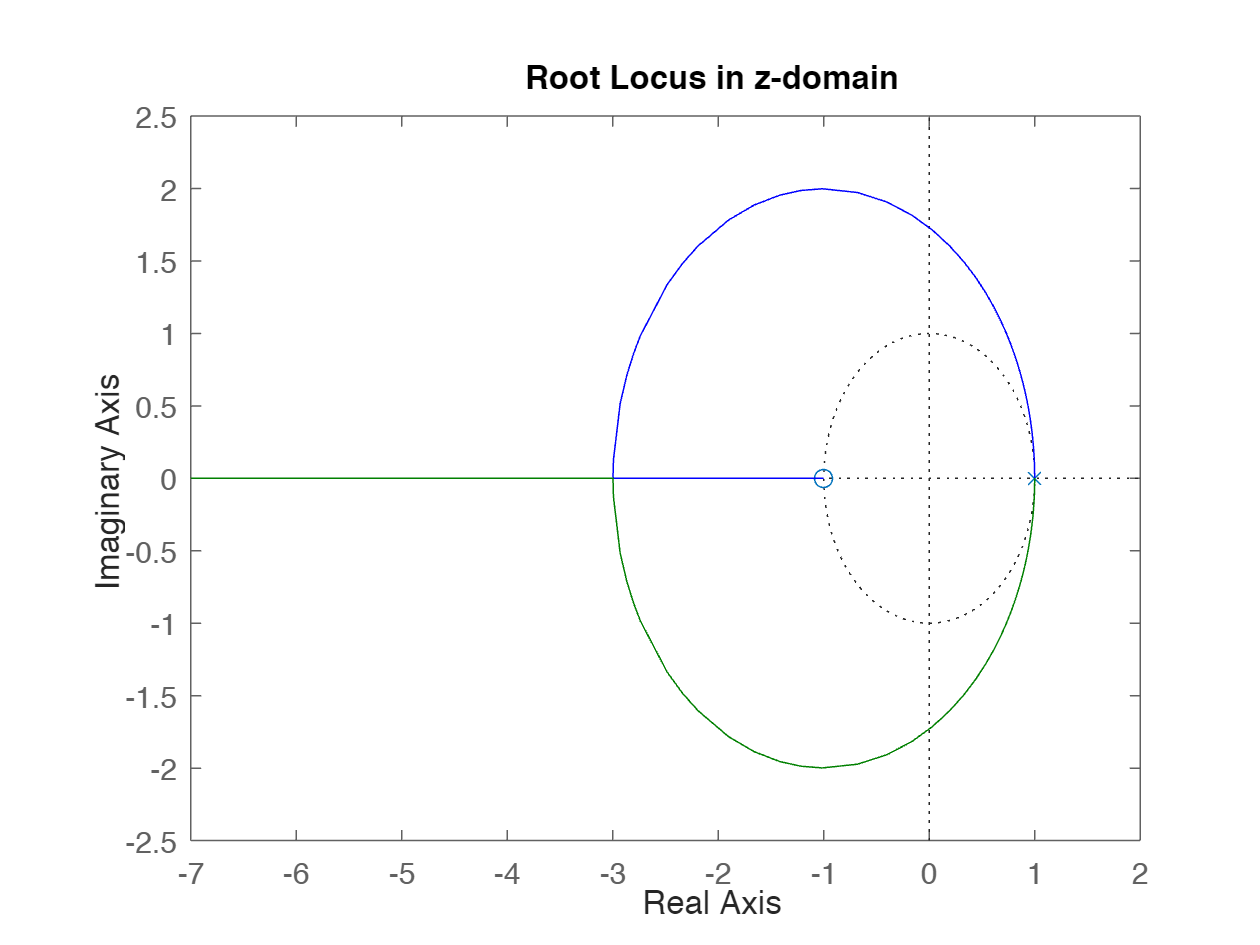


%Plot Root Locus in z domain
rlocus(Gp_ol_z);
title("Root Locus in z-domain");

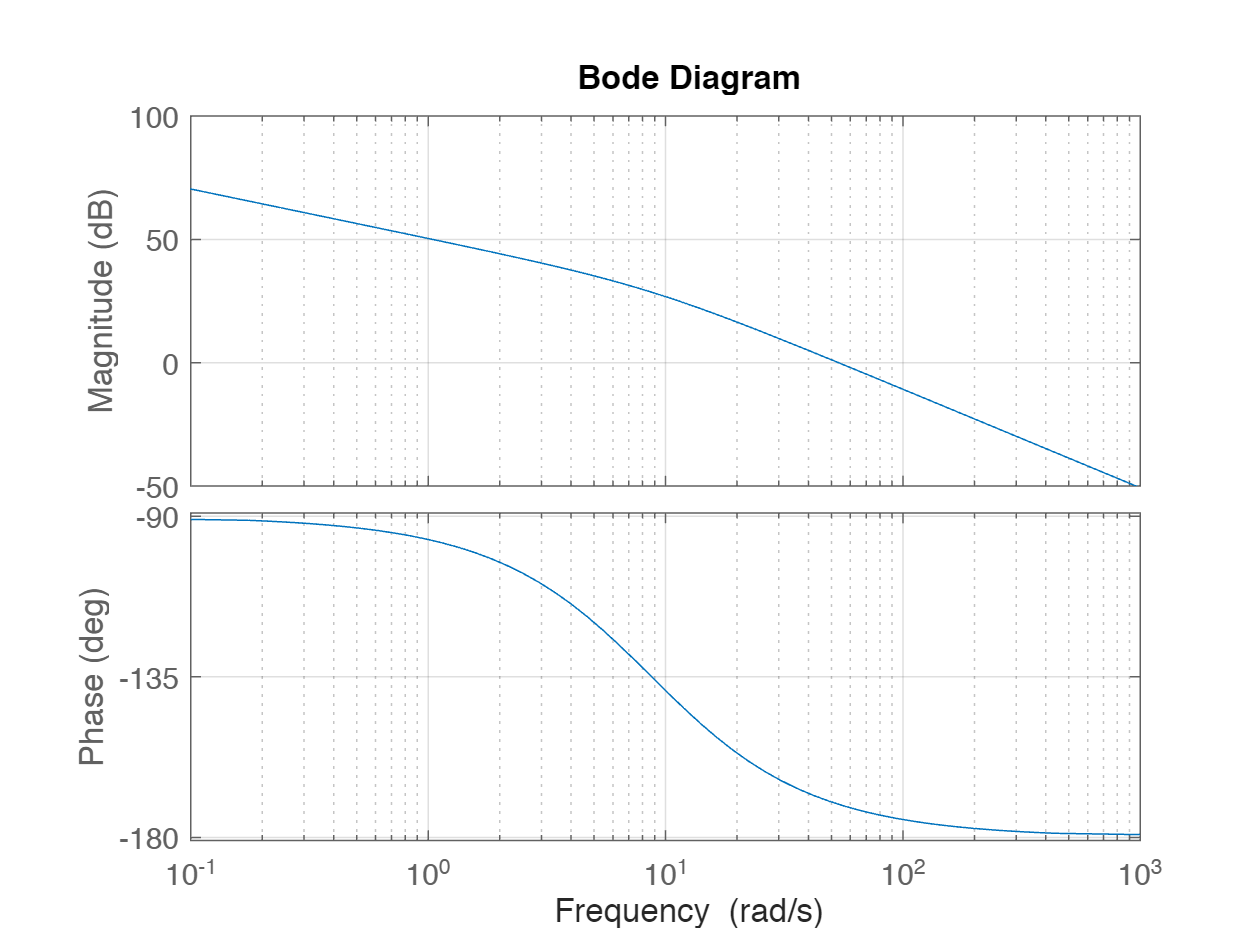




bode(Gp_ol_s);
grid on;

[gm_s, pm_s, wcg_s, wcp_s]=margin(Gp_ol_s)

gm_s = Inf

pm_s = 9.2753

wcg_s = Inf

wcp_s = 53.5343

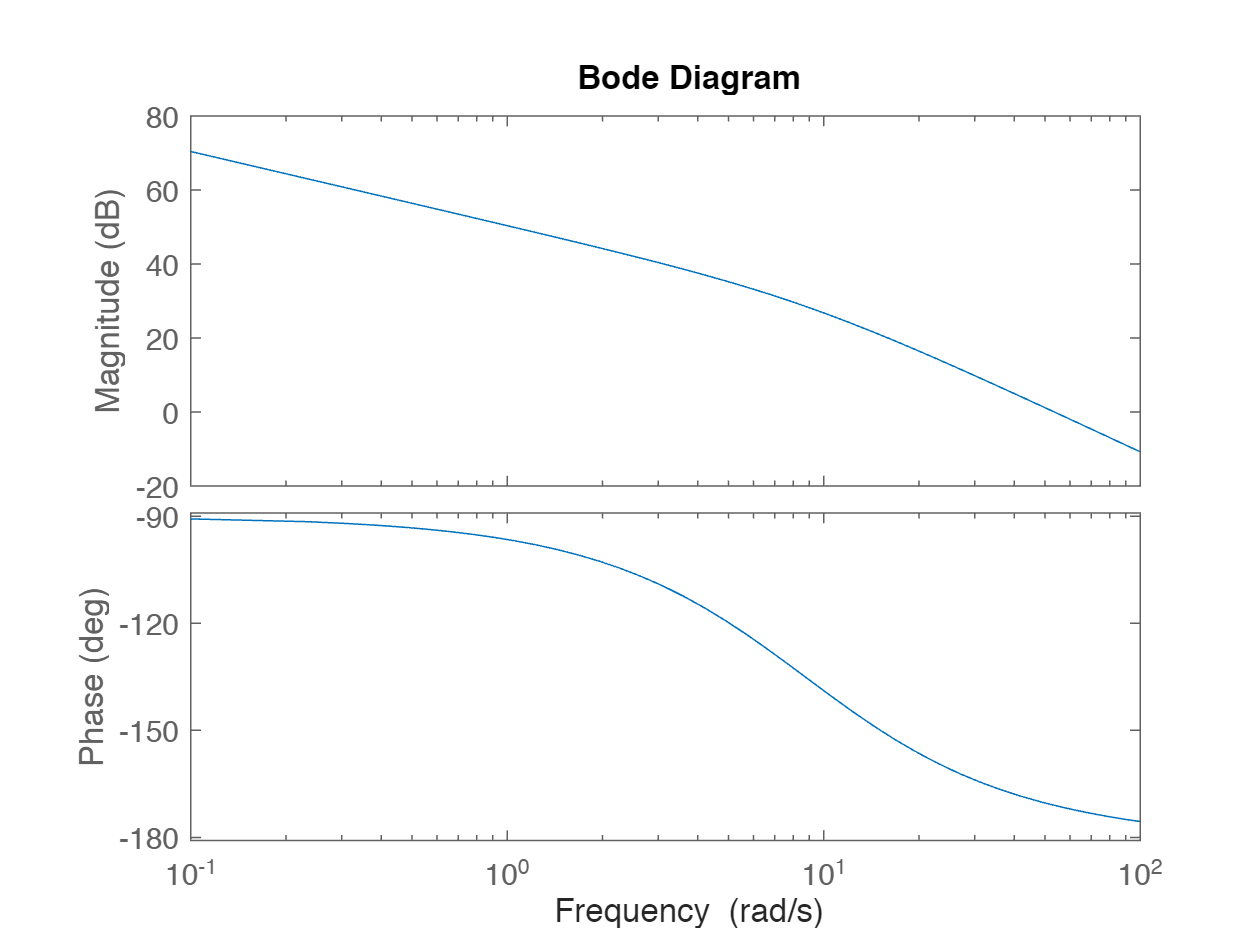


Ts=0.2;
 for i=1:3
    Ts=Ts/10;                                   
    sysd1=c2d(Gp_ol_s,Ts); 
    bode(sysd1);
    [gm(i), pm(i), wcg(i), wcp(i)]=margin(sysd1);

end

Gm_dB=20*log10(gm)

Gm_dB =   -10.1692    9.5989   29.5754


pm

pm =   -20.3033    6.2105    8.9671


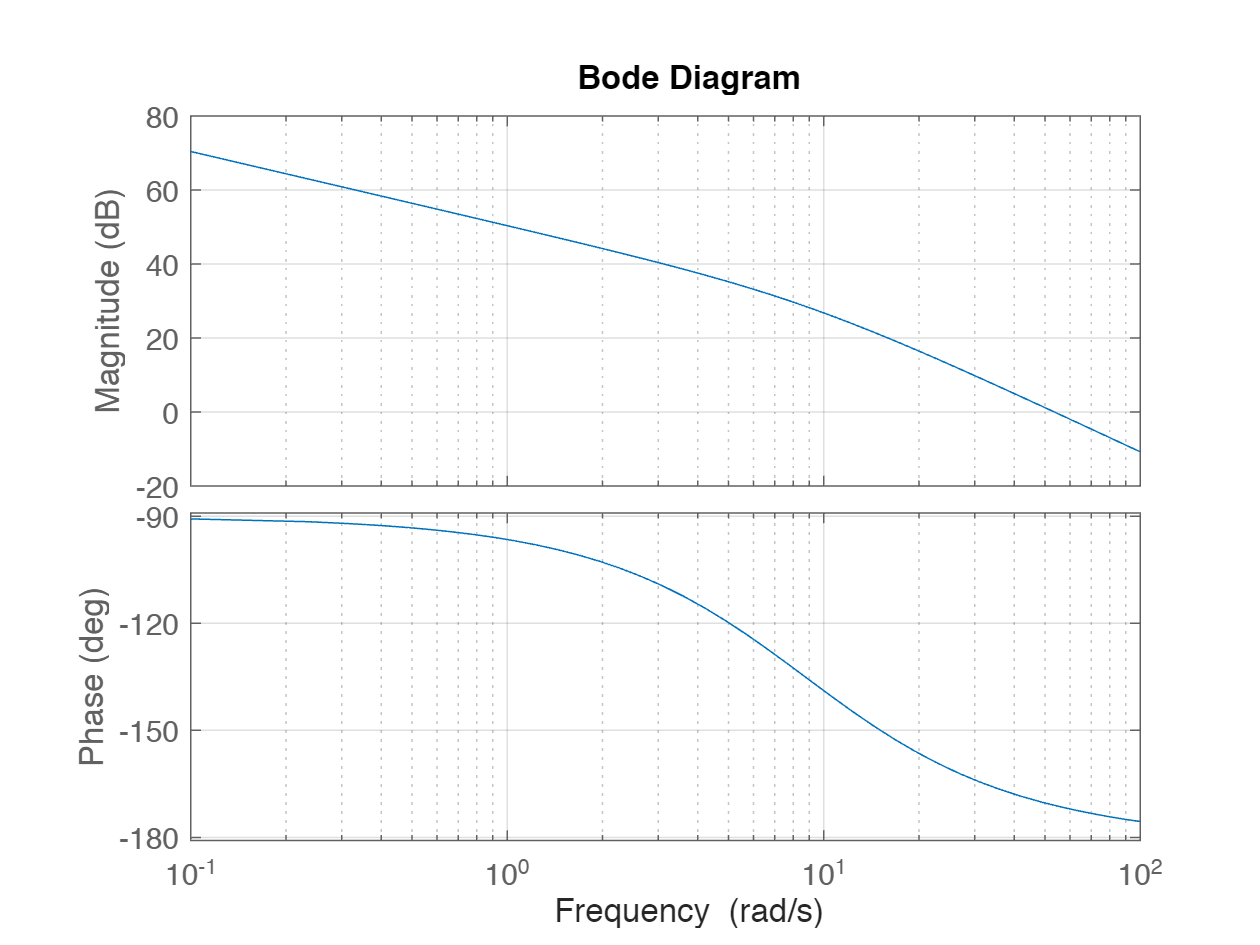

% Prelab Part 4
desired_crossover=60;           %rad/s
[mag,~]=bode(Gp_ol_z,desired_crossover);
grid on;

Kp=1/mag

Kp = 1.2527

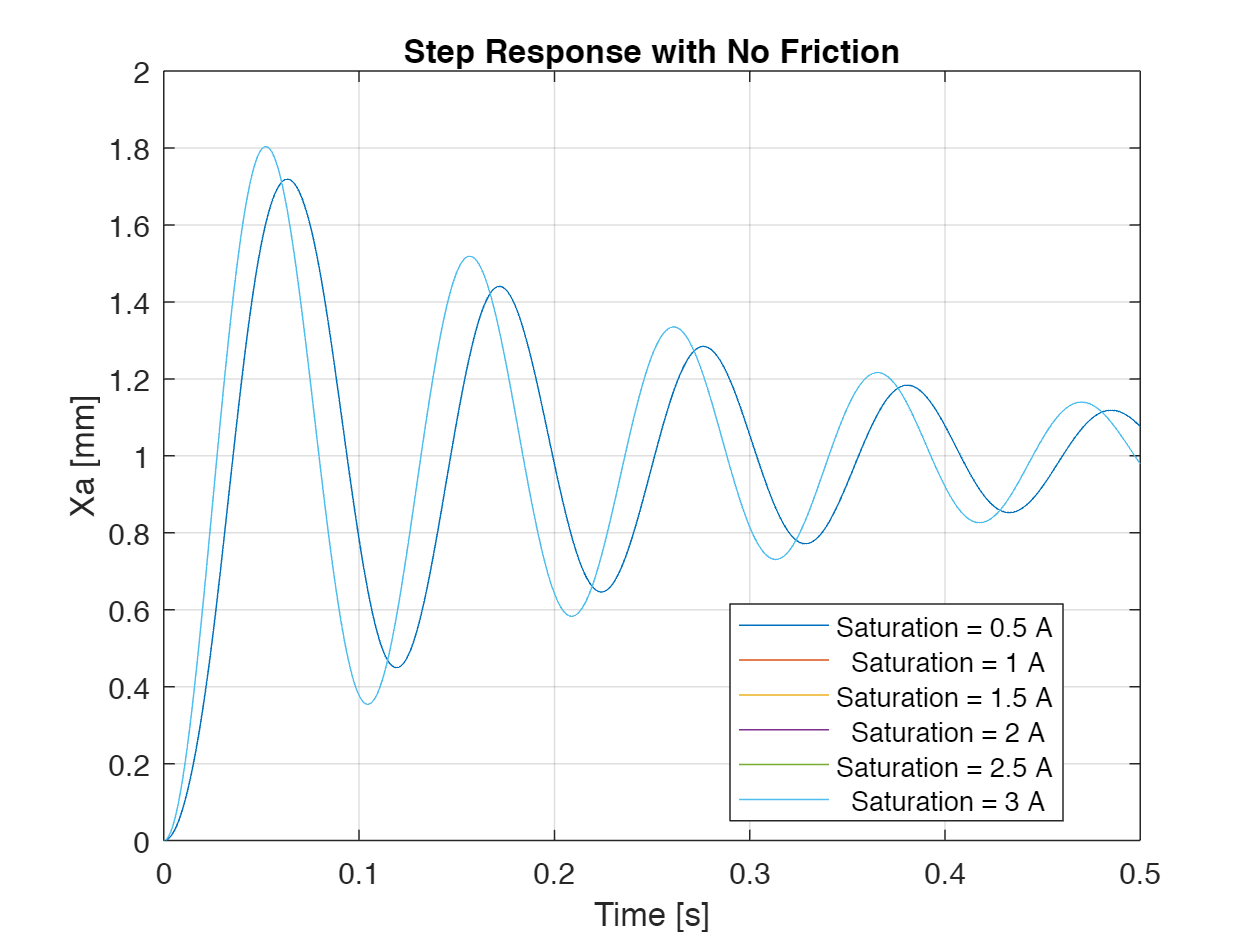


mu = 0.0;
for saturation_val = 0.5:0.5:3
    saturation = saturation_val;

    sim("C:\Users\Lachlan Reynolds\Downloads\Tutorial_5_Simulink0x2810x29.slx");
    
    plot(simout1.time, simout1.signals.values);
    hold on; % Add this line to overlay multiple plots on the same figure
end


title("Step Response with No Friction" );
xlabel("Time [s]");
ylabel("Xa [mm]");
legend(cellstr(num2str((0.5:0.5:3)', 'Saturation = %g A')), 'Location', 'Best');
grid on;

RT=[0 0.63];

mu=0.1;
figure(); % Move figure creation outside the inner loop
for i = 1:3
    saturation = 3;

    sim("C:\Users\Lachlan Reynolds\Downloads\Tutorial_5_Simulink0x2810x29.slx");

    %plot step
    plot(simout1.time, simout1.signals.values);
    hold on; % Add this line to overlay multiple plots on the same figure
    k_overshoot_sim(i)=(max(simout1.signals.values)-1);
    S(i)=stepinfo(simout1.signals.values,simout1.time, 'RiseTimeLimits', RT);
    k_rt_sim(i)=S(i).RiseTime;

    title("Step Response vs Time");
    xlabel("Time [s]");
    ylabel("Xa [mm]");
    legend(cellstr(num2str((0.1:0.1:0.3)', 'mu = %g')), 'Location', 'Best');
    grid on;
    hold off;

    mu = mu + 0.1;
end

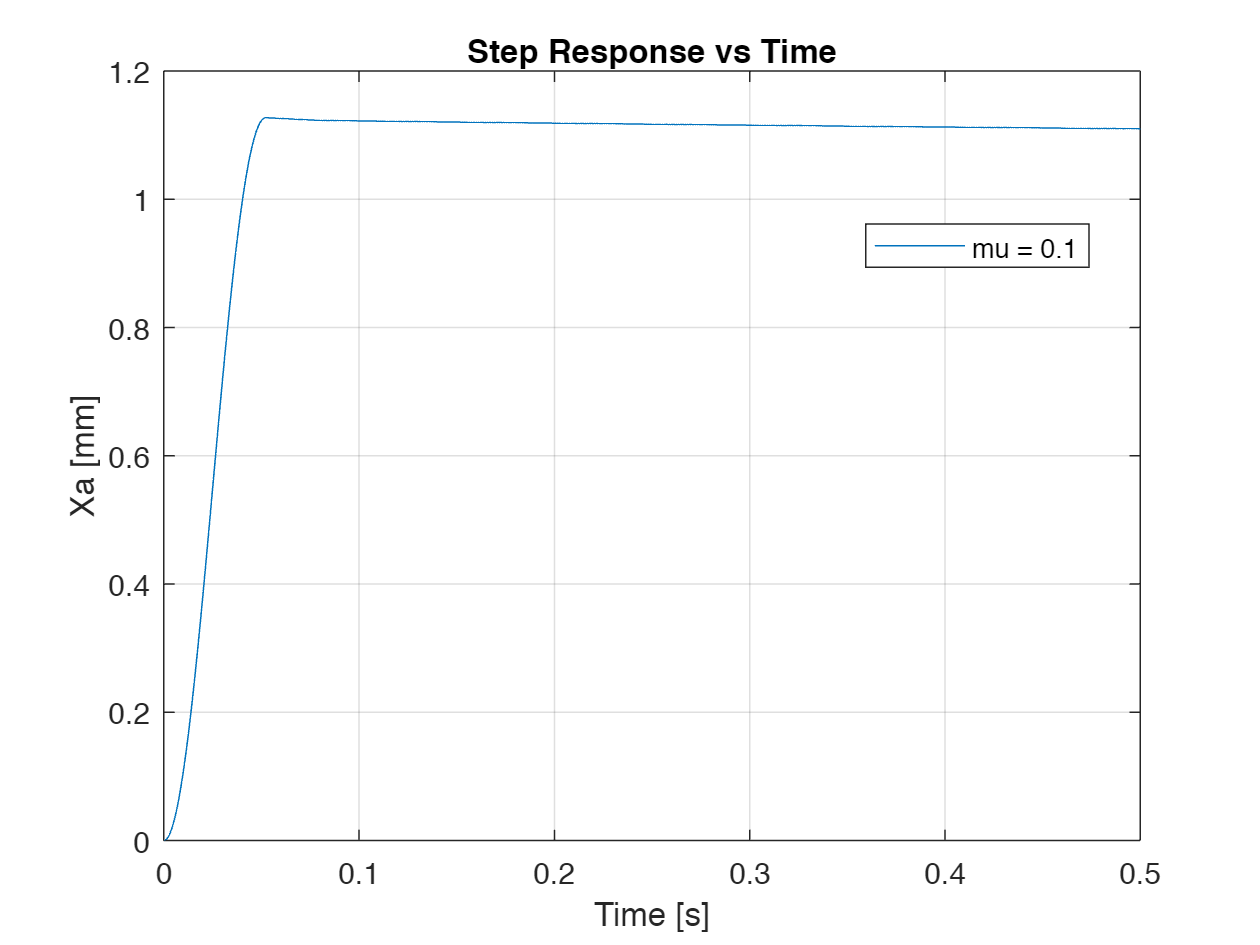

hold off;



mu=0.1;
figure(); % Move figure creation outside the inner loop
for i = 1:3
    saturation = 3;

    sim("C:\Users\Lachlan Reynolds\Downloads\Tutorial_5_Simulink0x2810x29.slx");

    %plot step
    plot(simout2.time, simout2.signals.values);
    hold on; % Add this line to overlay multiple plots on the same figure
 
    k_sserror_sim(i)=(simout2.signals.values(end-1)-2.5);

    title("Ramp Response vs Time");
    xlabel("Time [s]");
    ylabel("Xa [mm]");
    legend(cellstr(num2str((0.1:0.1:0.3)', 'mu = %g')), 'Location', 'Best');
    grid on;
    hold off;

    mu = mu + 0.1;
end

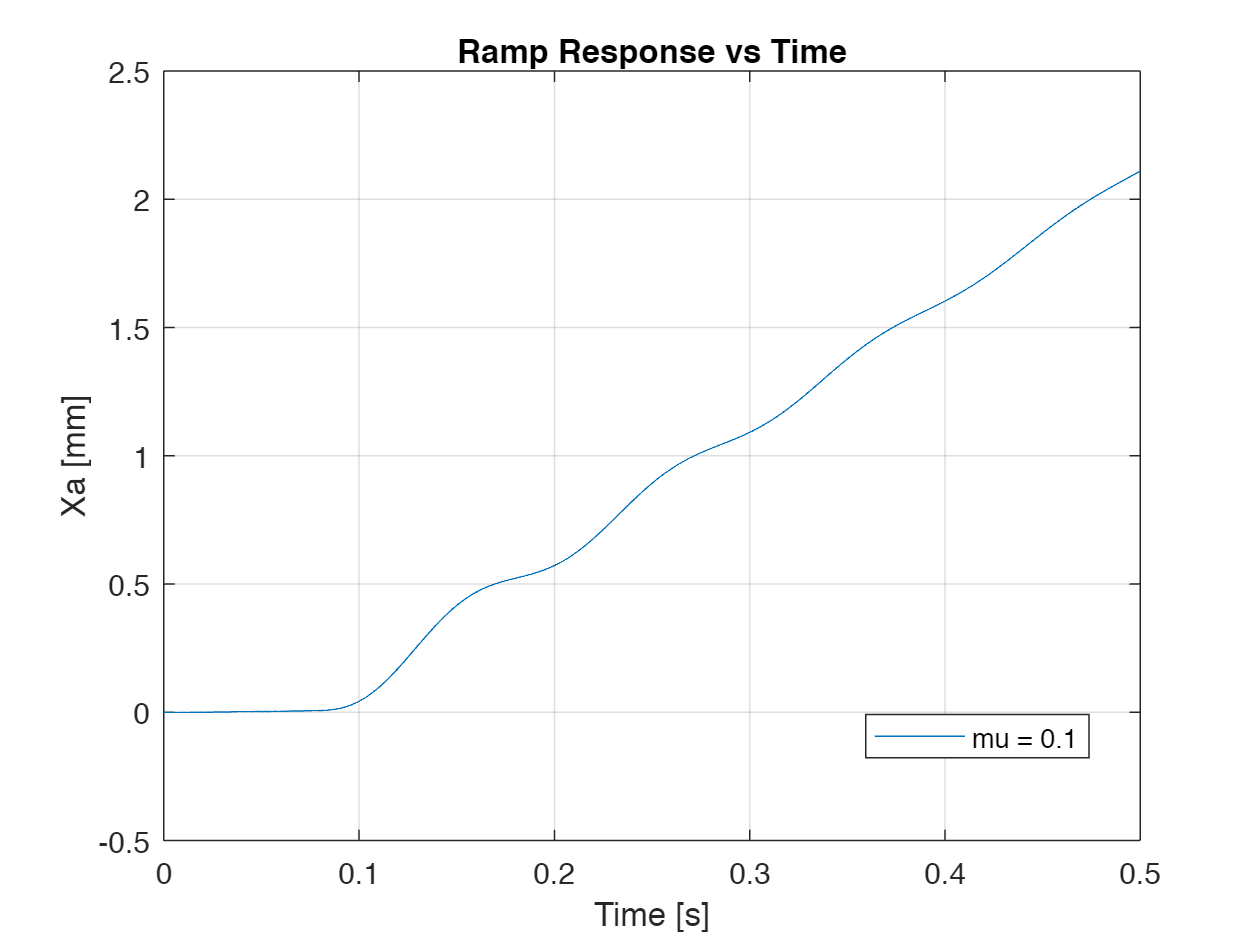

hold off;

% Pre-lab Question 5
% Lead Lag (LL)
crossover_freq=60*2*pi;
desired_PM=60;


phi_m=180*(-pi/2-atan(crossover_freq/p1))/pi;
phase_to_add=desired_PM-(180+phi_m)

phase_to_add = 58.6715

phase_to_add=phase_to_add*pi/180;           %in rad now

alpha=(1+sin(phase_to_add))/(1-sin((phase_to_add)))

alpha = 12.7174


T=1/(crossover_freq*sqrt(alpha))

T = 7.4382e-04


K=1; %initially set to 1

%determine transfer
num_LL=K*[alpha*T 1];
den_LL=[T 1];
C=tf(num_LL, den_LL);                           

%plot Bode
[mag, ~]=bode(C*Gp_ol_s, crossover_freq)

mag = 0.0728

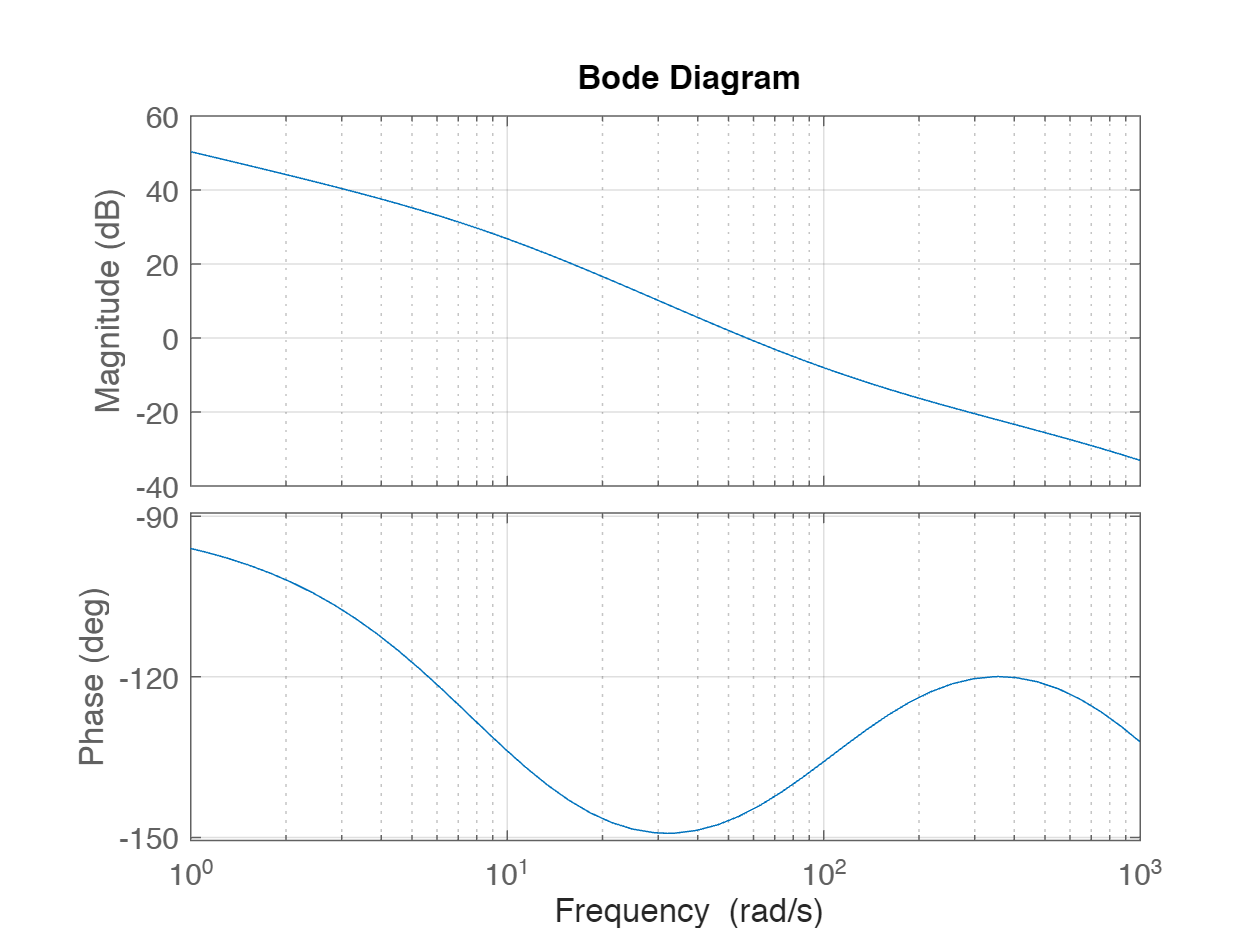

bode(C*Gp_ol_s)
xlim([1 1e3]);
grid on;

K=1/mag %determine K

K = 13.7269


%re do transfer func with new K
num_LL=K*[alpha*T 1];
den_LL=[T 1];
C=tf(num_LL, den_LL);                           
[mag, phase]=bode(C*Gp_ol_s, crossover_freq)

mag = 1.0000

phase = -120.0000

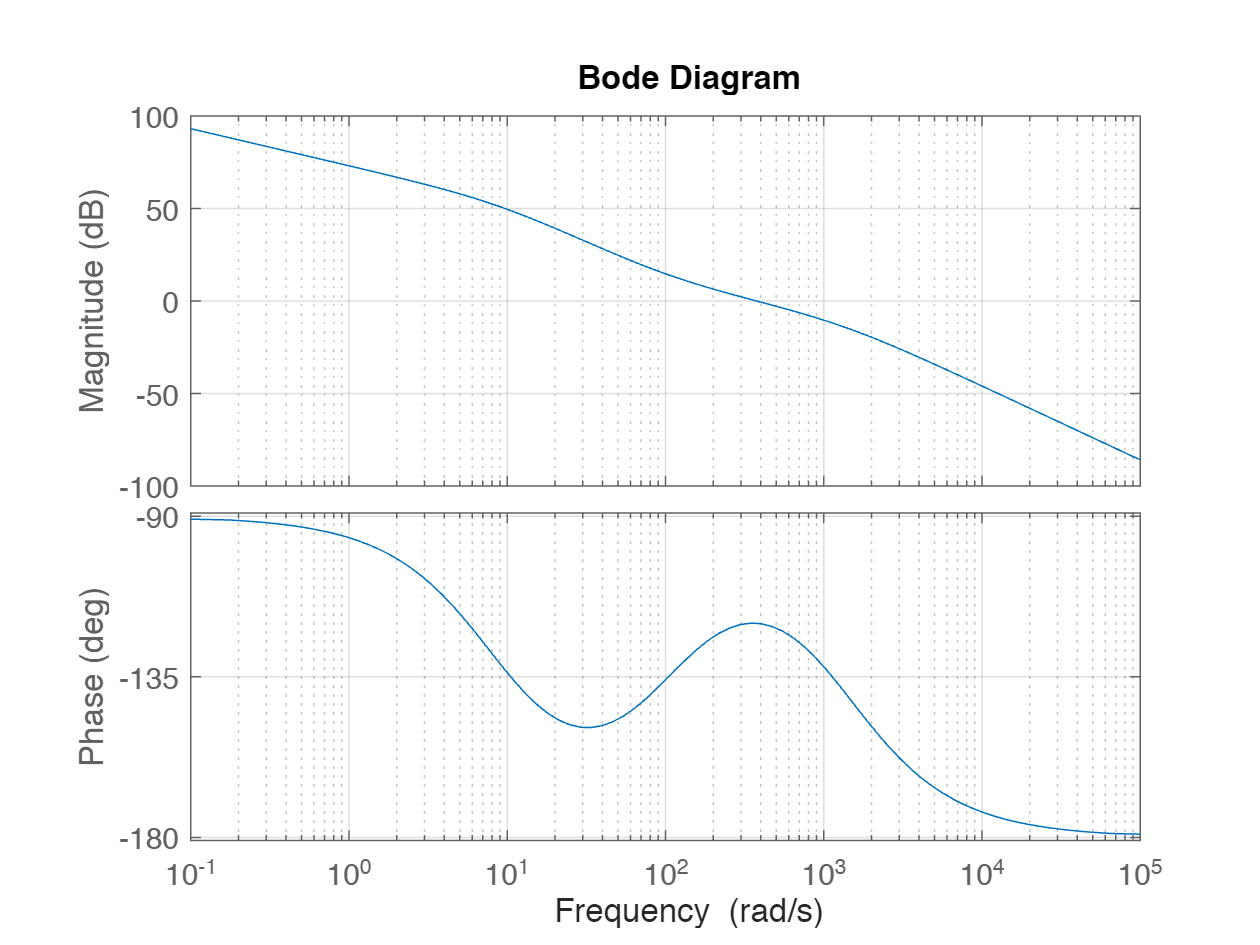

bode(C*Gp_ol_s)
grid on;



%I Integrator
Ki=crossover_freq/10;
num_I=[1 Ki];
den_I=[1 0];
I=tf(num_I, den_I);

LL_d=c2d(C,Ts,"tustin")

LL_d =
 
  155.5 z - 152.3
  ---------------
     z - 0.763
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


I_d=c2d(I,Ts,"tustin")

I_d =
 
  1.004 z - 0.9962
  ----------------
       z - 1
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


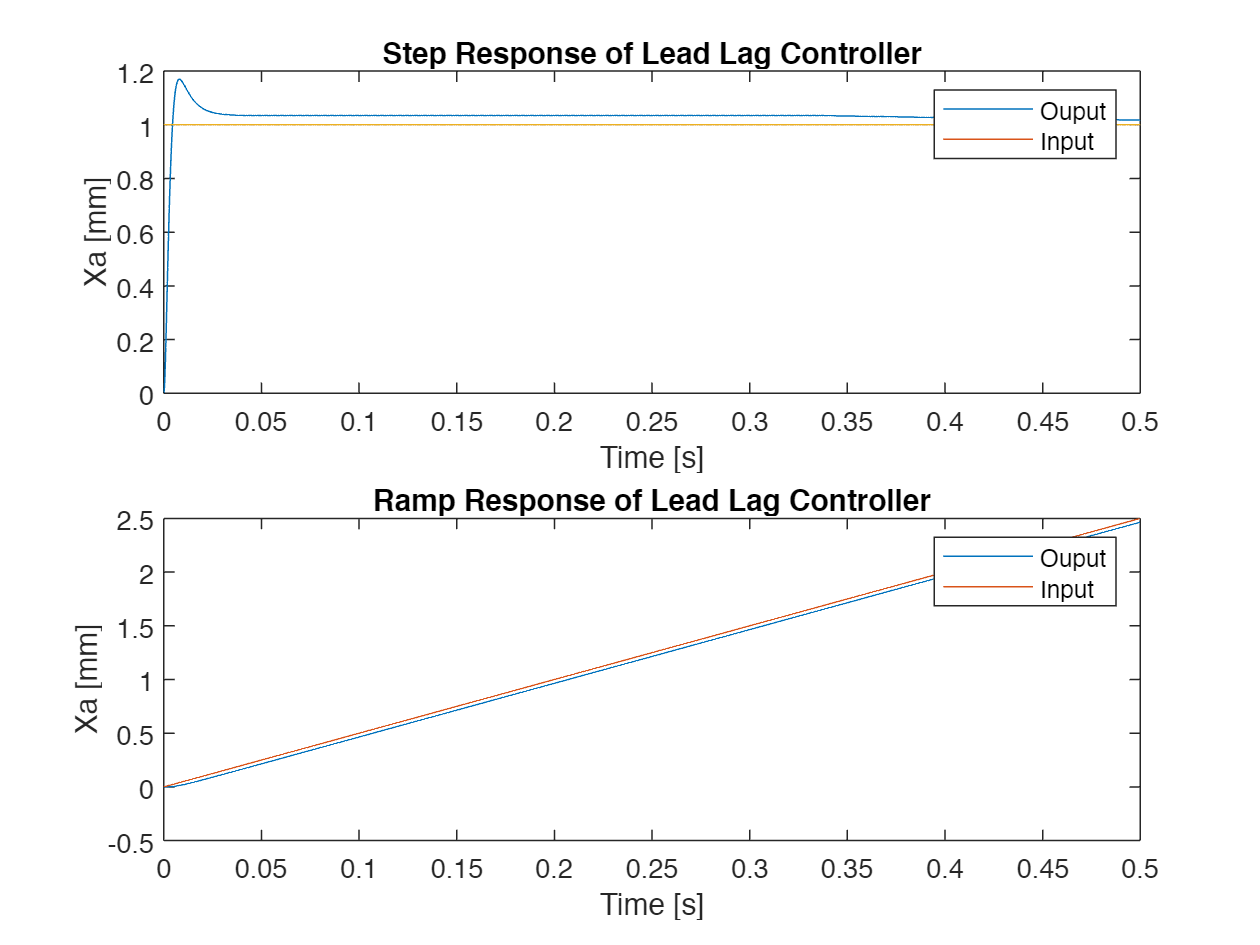


[LL_d_num, LL_d_den] = tfdata(LL_d, 'v');
[I_d_num, I_d_den] = tfdata(I_d, 'v');

% LL
figure;
mu=0.3;
sim("C:\Users\Lachlan Reynolds\Downloads\Tutorial_5_Simulink0x2810x29.slx");

%Just LL Step
subplot(2,1,1);
plot(simout3.time, simout3.signals.values);
hold on;
step_LL=ones(length(simout.time));
plot(simout3.time, step_LL);
hold off;
title("Step Response of Lead Lag Controller");
xlabel("Time [s]");
ylabel("Xa [mm]");
legend("Ouput", "Input");

LL_overshoot_sim(i)=(max(simout3.signals.values)-1);
S(i)=stepinfo(simout3.signals.values,simout1.time, 'RiseTimeLimits', RT);
LL_rt_sim(i)=S(i).RiseTime;

subplot(2,1,2);
plot(simout5.time, simout5.signals.values);
hold on;
ramp_LL=5*simout.time;
plot(simout3.time, ramp_LL);
hold off;
title("Ramp Response of Lead Lag Controller");
xlabel("Time [s]");
ylabel("Xa [mm]");
legend("Ouput", "Input");

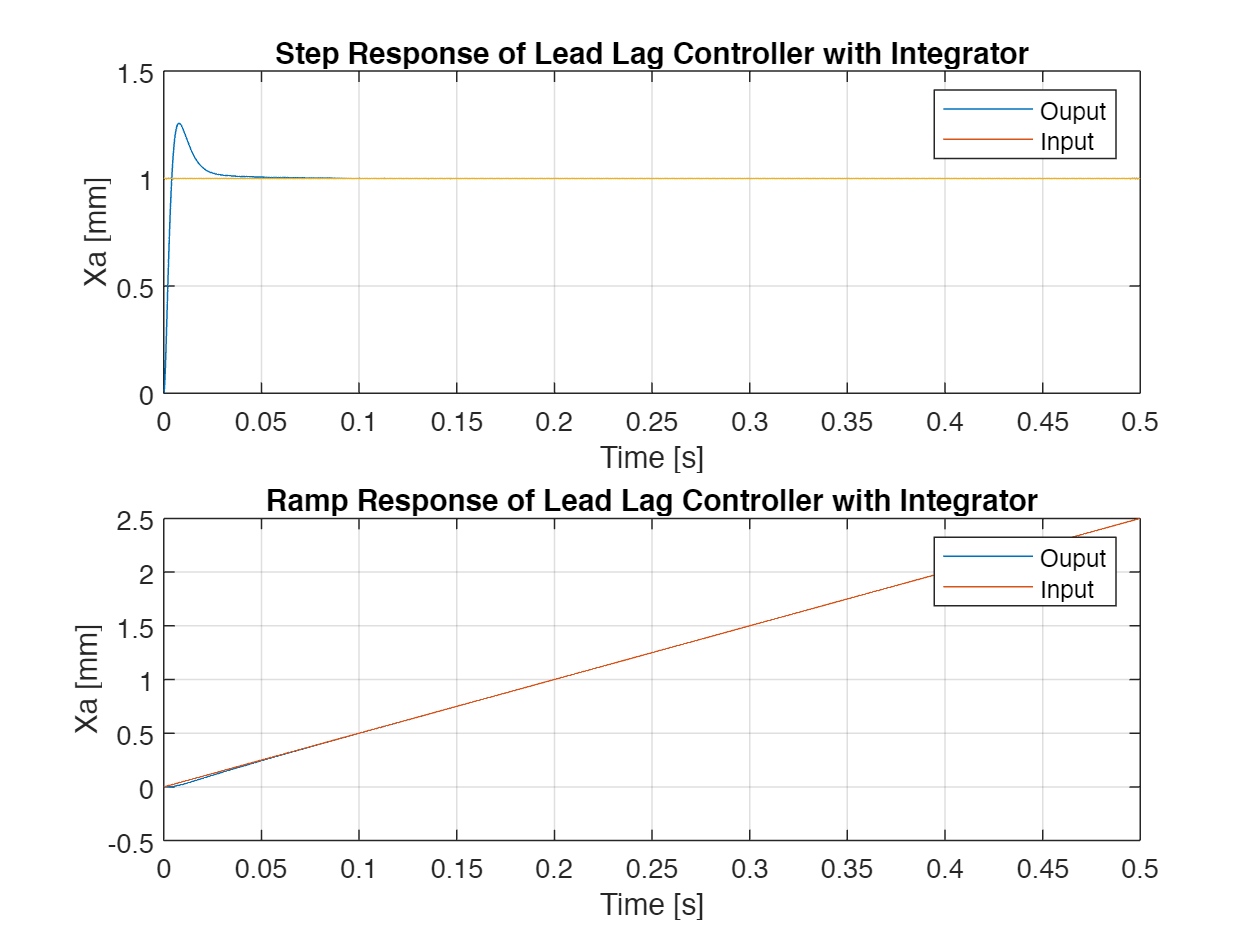

LL_sserror_sim=(simout5.signals.values(end-1)-ramp_LL(end-1));


%% LLI 
figure;
subplot(2,1,1);
plot(simout4.time, simout4.signals.values);
hold on;
step_LLI=ones(length(simout.time));
plot(simout4.time, step_LLI);
hold off;
title("Step Response of Lead Lag Controller with Integrator");
xlabel("Time [s]");
ylabel("Xa [mm]");
legend("Ouput", "Input");
grid on;
LLI_overshoot_sim=max(simout4.signals.values);
S=stepinfo(simout4.time, simout4.signals.values, 'RiseTimeLimits', RT);
LLI_rt_sim=S.RiseTime;


subplot(2,1,2);
plot(simout6.time, simout6.signals.values);
hold on;
ramp_LLI=5*simout.time;
plot(simout6.time, ramp_LLI);
hold off;
title("Ramp Response of Lead Lag Controller with Integrator");
xlabel("Time [s]");
ylabel("Xa [mm]");
legend("Ouput", "Input");
grid on;

LLI_sserror_sim=(simout6.signals.values(end-1)-ramp_LL(end-1));




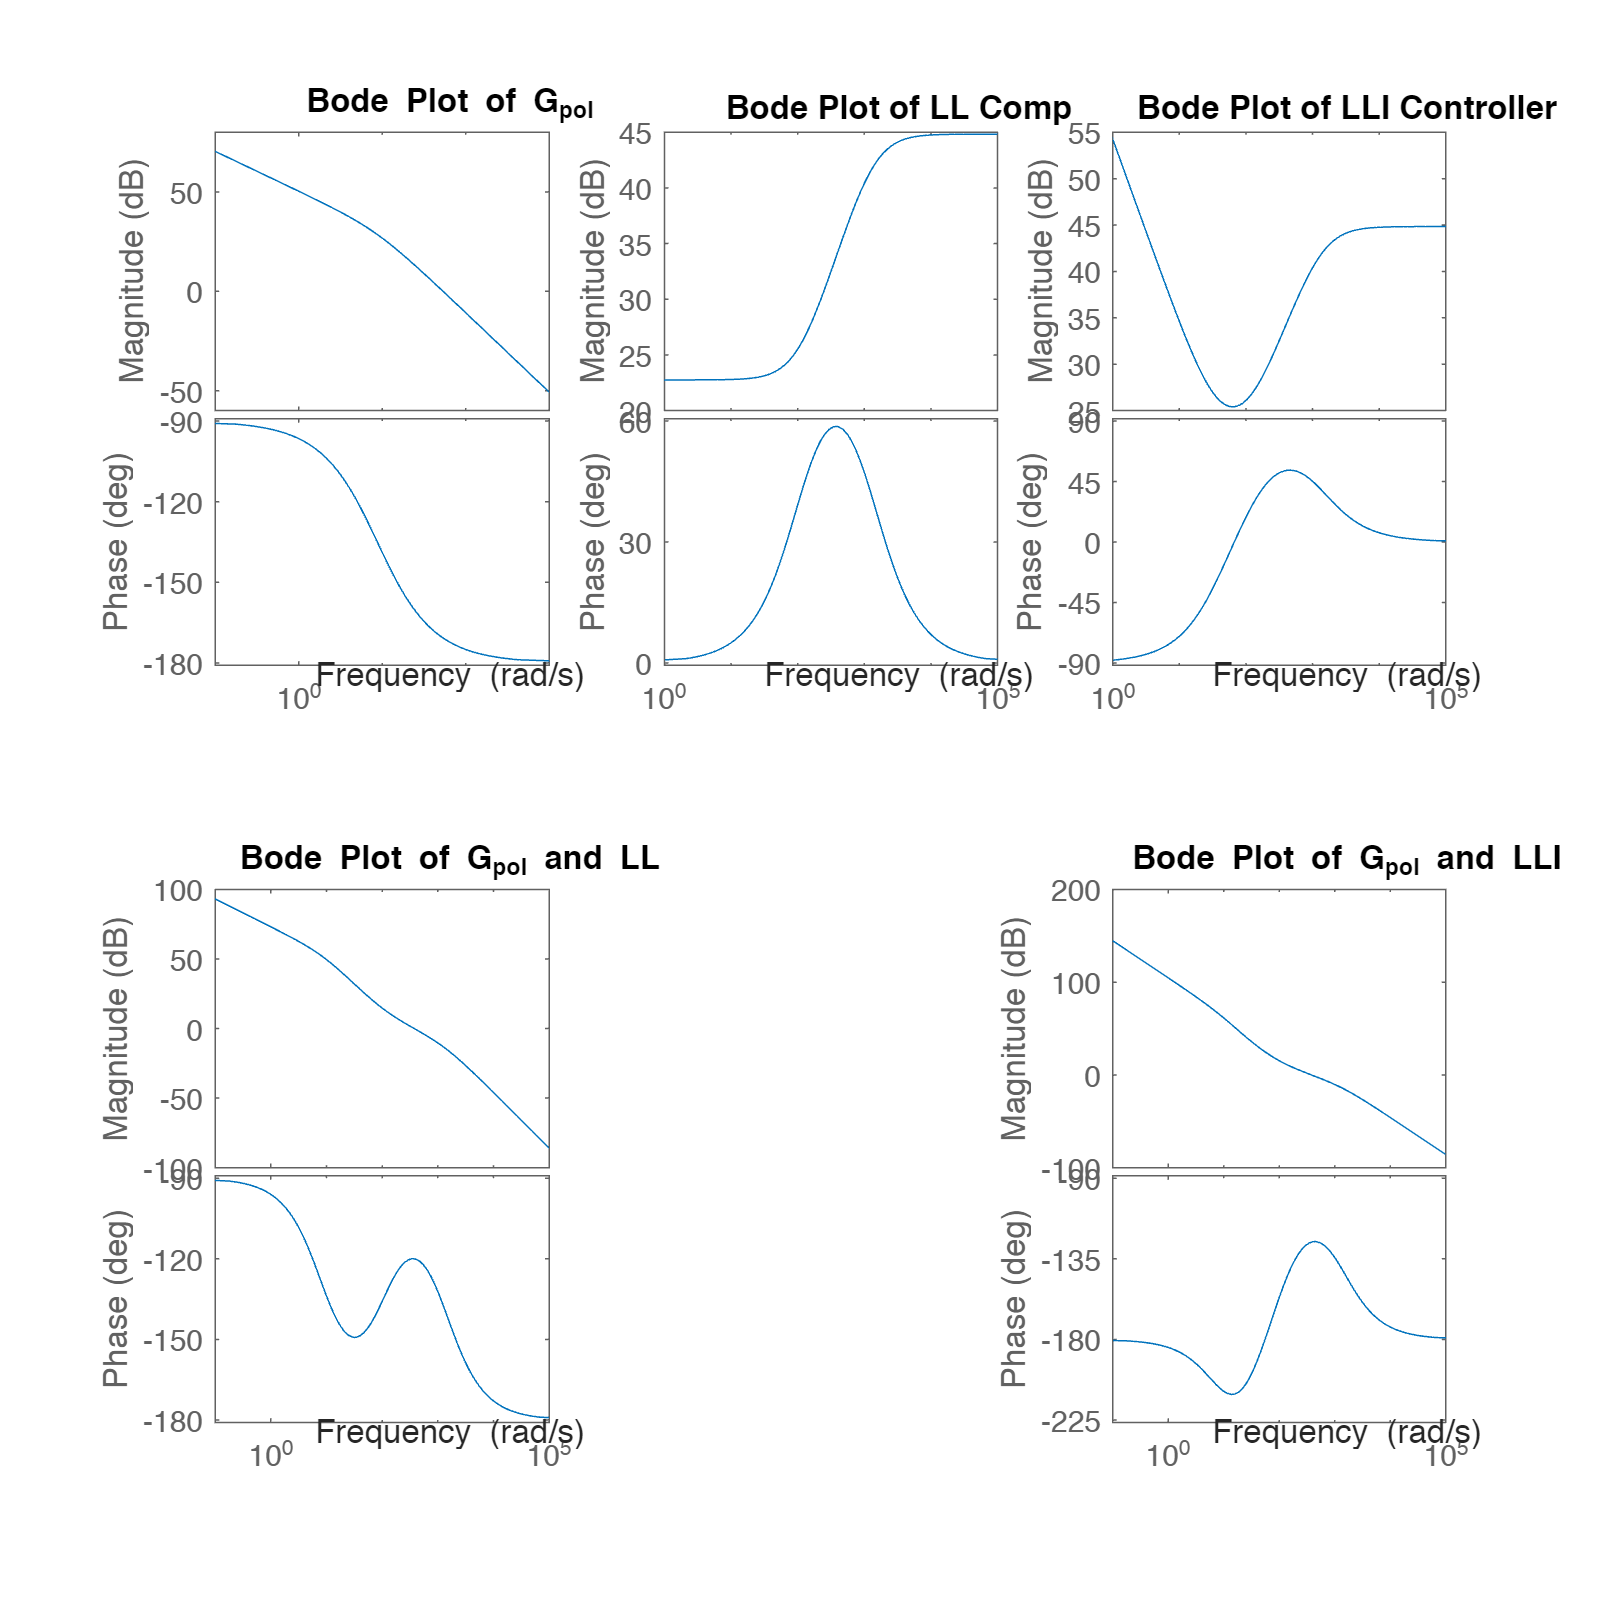

% Prelab 6. Discussion

figure('Position', [500, 200, 2500, 2500]);
subplot(2,3,1);
bode(Gp_ol_s); %Gol(s)
title("Bode Plot of G_pol");


subplot(2,3,2);
bode(C);                % LL
title("Bode Plot of LL Comp");

subplot(2,3,3);
bode(C*I);                 %LLI
title("Bode Plot of LLI Controller");


subplot(2,3,4);
bode(Gp_ol_s*C);       % Gol(s)*LL
title("Bode Plot of G_pol and LL");


subplot(2,3,6);
bode(Gp_ol_s*C*I);       % Gol(s)*LLI
title("Bode Plot of G_pol and LLI");
hold off;

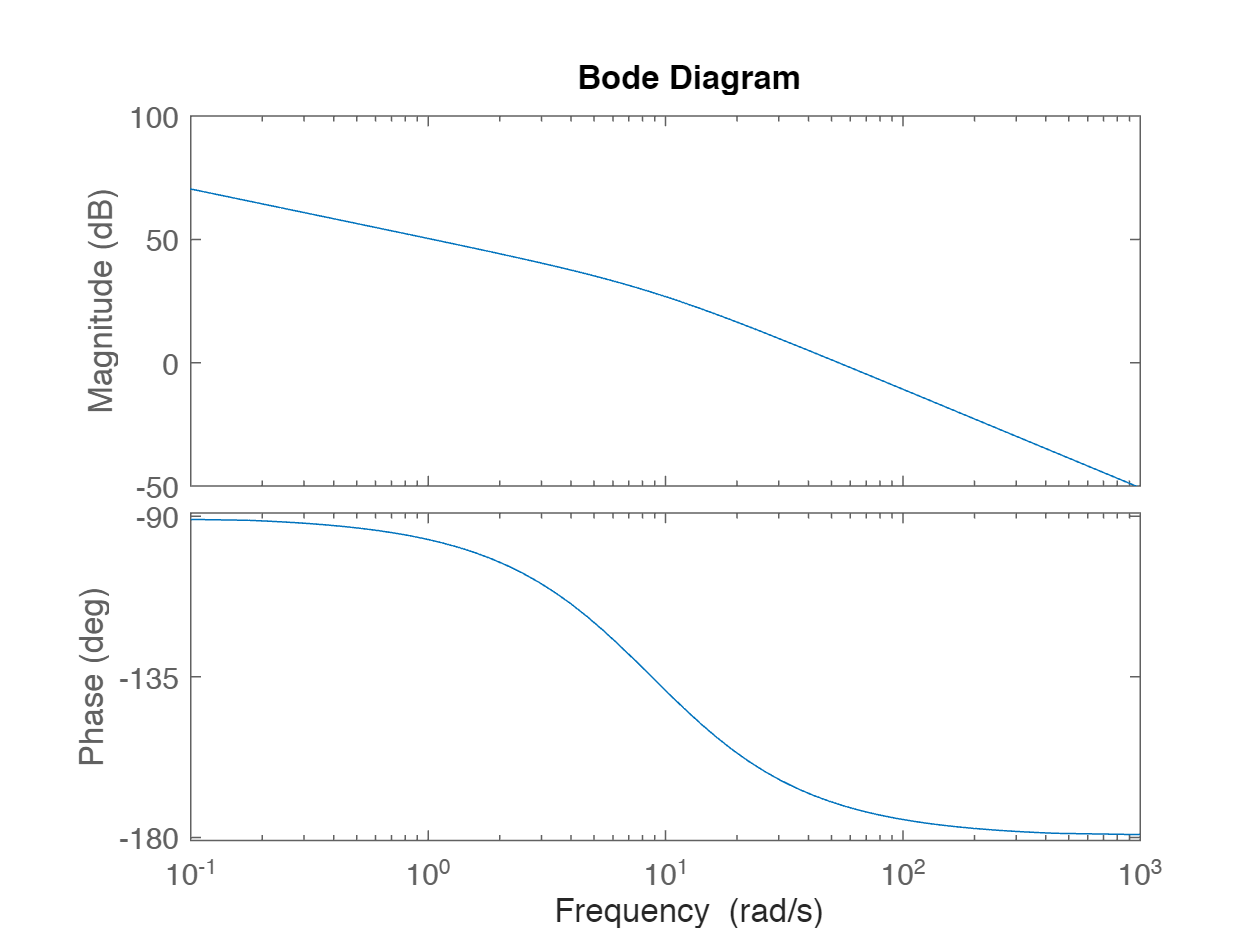

% better graphs for 6
figure();
bode(Gp_ol_s); %Gol(s)
hold off;

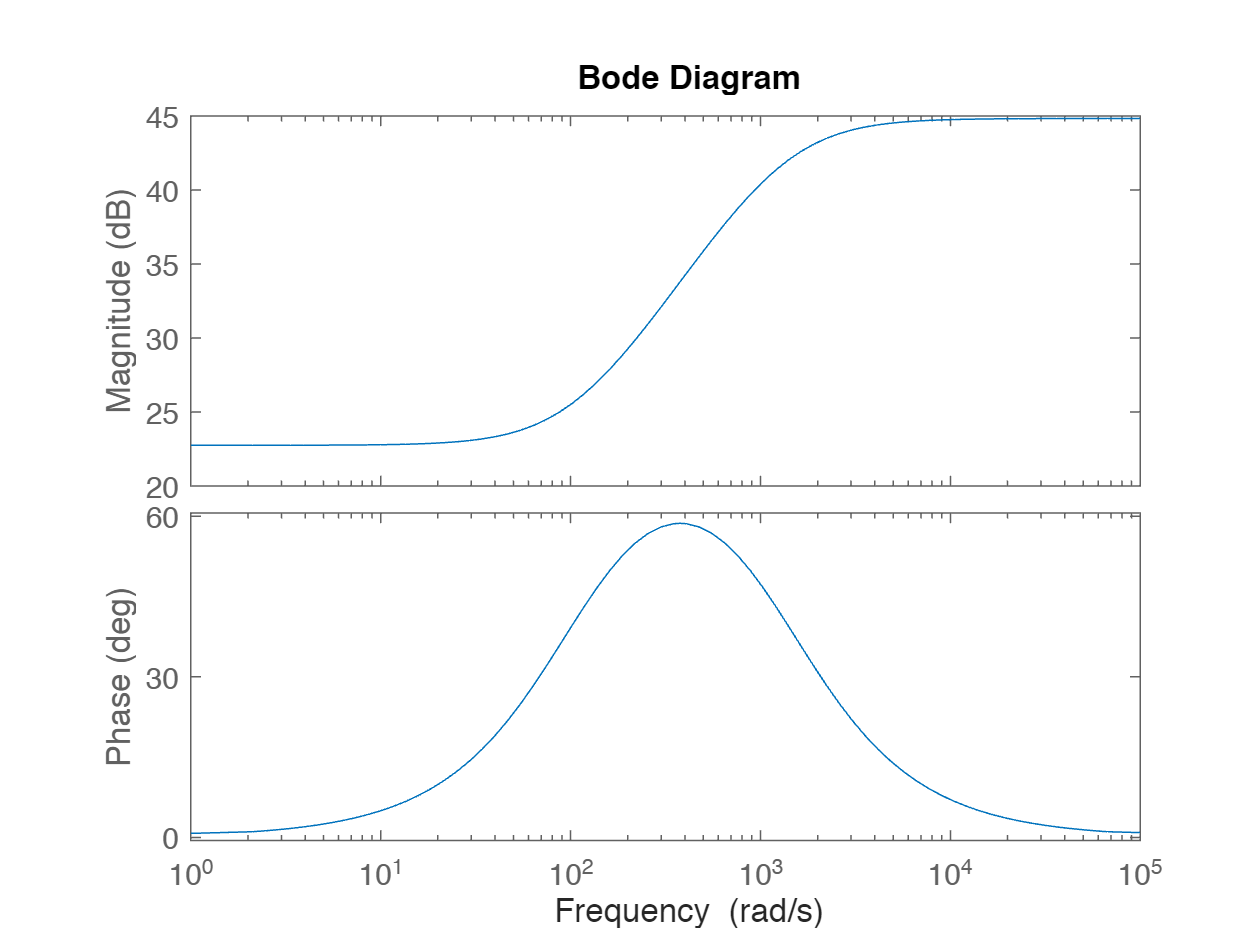

bode(C);                % LL
hold off;

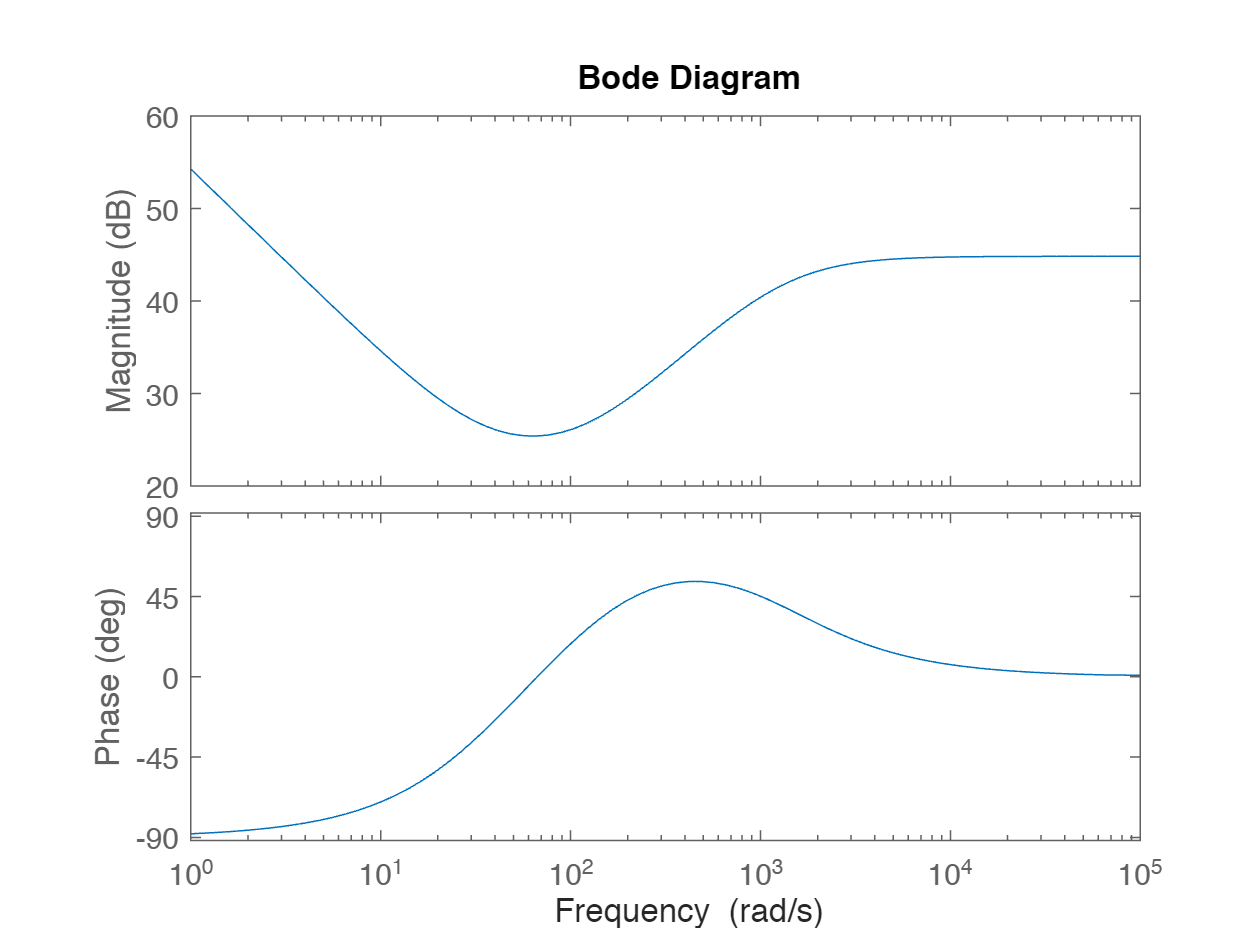

bode(C*I);                 %LLI
hold off;

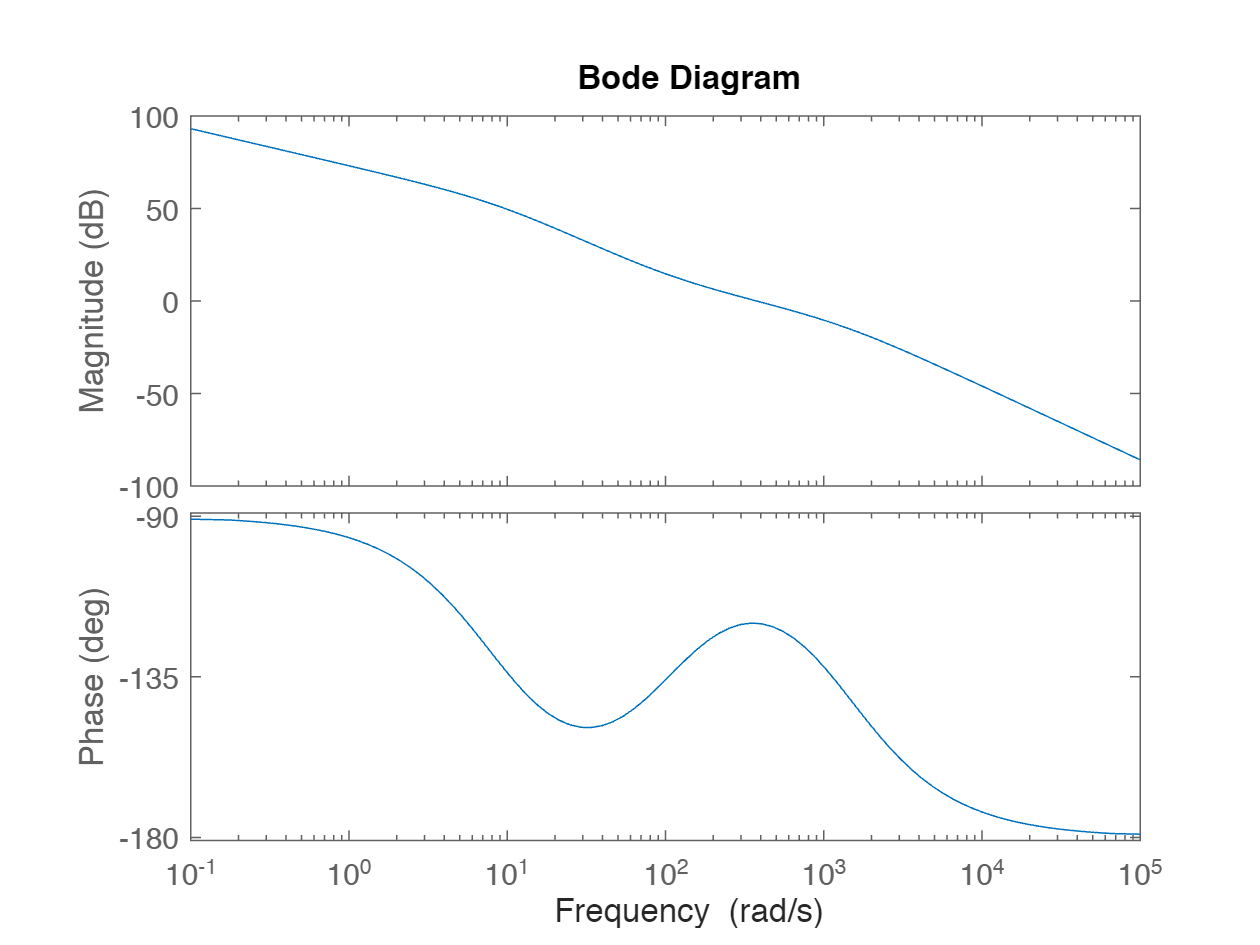

bode(Gp_ol_s*C);       % Gol(s)*LL
hold off;

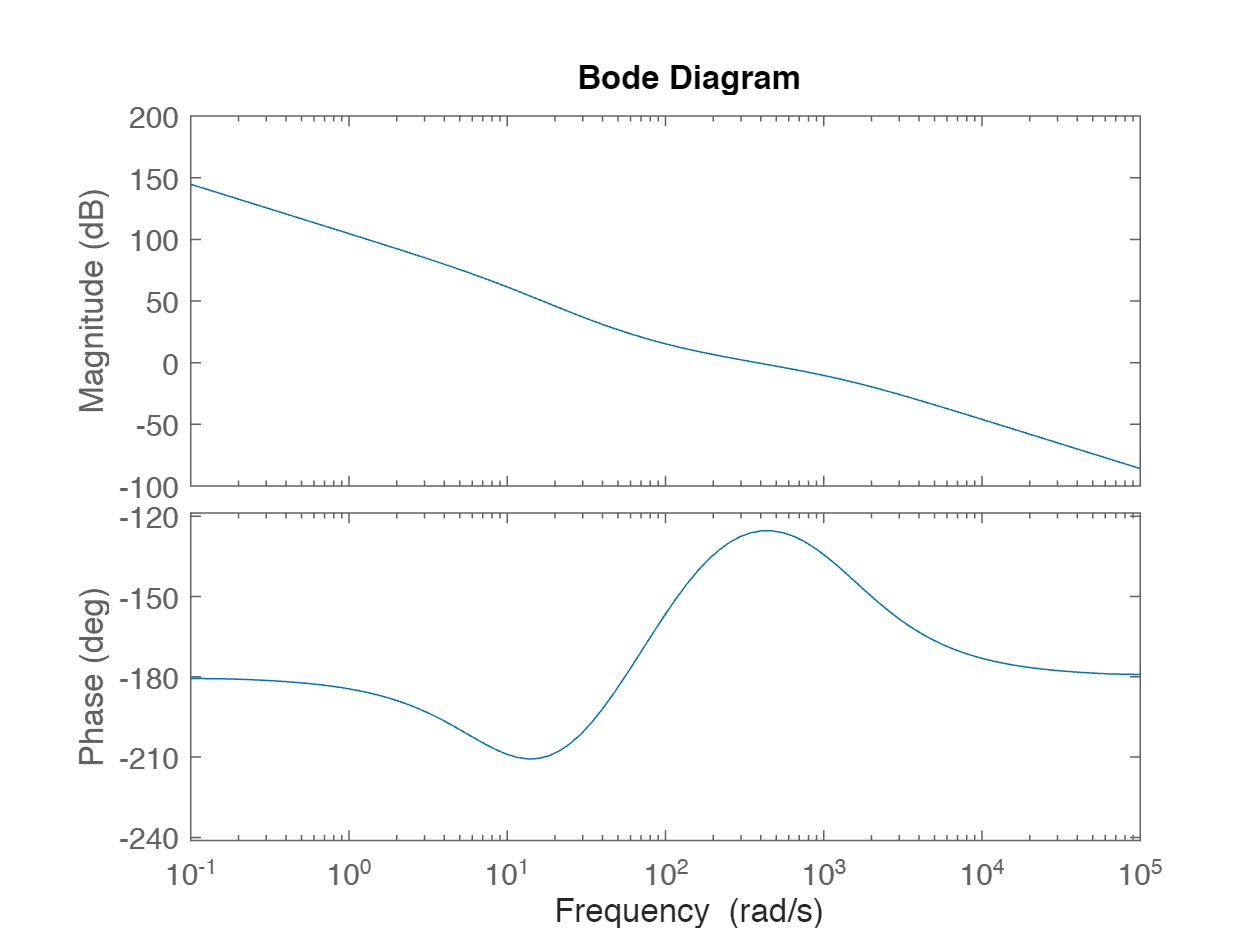

bode(Gp_ol_s*C*I);       % Gol(s)*LLI
hold off;

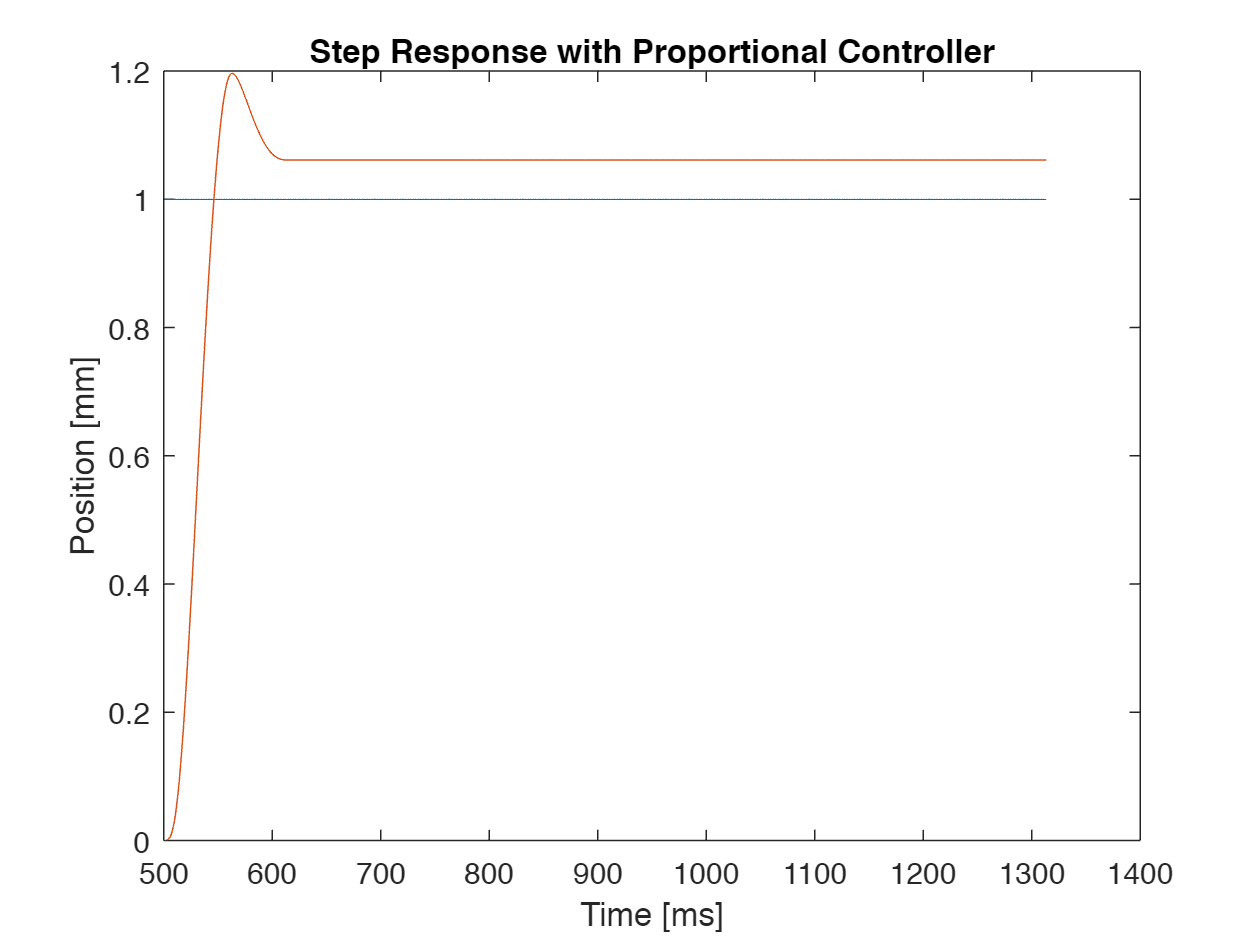

% Experimental data: Kp
% Kp controller Step
time_start_step=.501/Ts;
data_k_step=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\k_s.csv", "NumHeaderLines",1);
time=data_k_step.Var1(time_start_step:end);
reference_trajectory=data_k_step.Var2(time_start_step:end);
position_mm=data_k_step.Var3(time_start_step:end);

plot(time,reference_trajectory);
hold on;
plot(time,position_mm);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Step Response with Proportional Controller");
hold off;

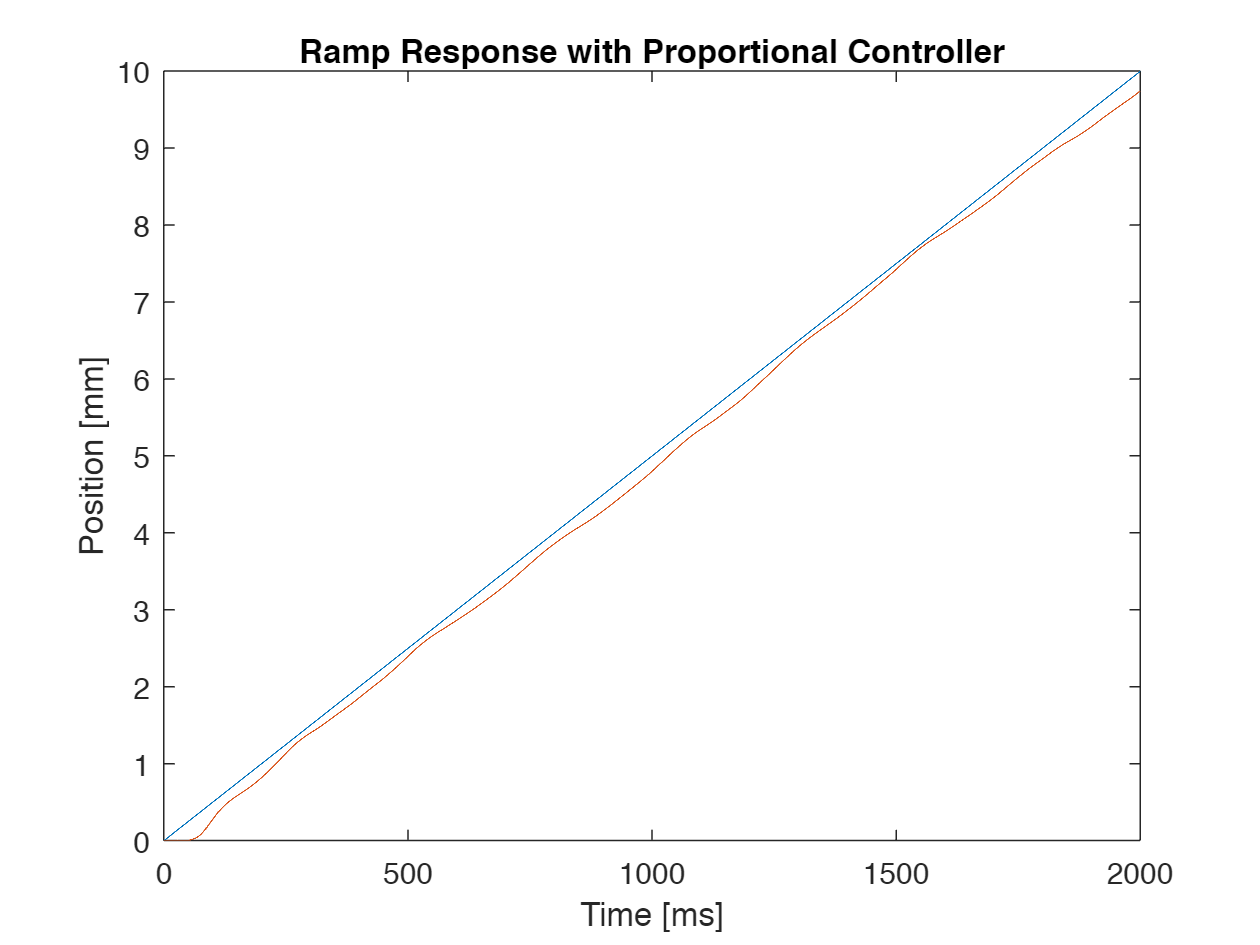


S_k_exp=stepinfo(position_mm, time,'RiseTimeLimits', RT); %0 to 63percent of 1
k_rt_exp=S_k_exp.RiseTime;
k_overshoot_exp=(max(position_mm)-1);

%kp controller ramp
max_ramp_time=10000;
data_k_ramp=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\k_r.csv", "NumHeaderLines",1);
time=data_k_ramp.Var1(1:max_ramp_time);
reference_trajectory=data_k_ramp.Var2(1:max_ramp_time);
position_mm_kp=data_k_ramp.Var3(1:max_ramp_time);


plot(time,reference_trajectory);
hold on;
plot(time,position_mm_kp);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Ramp Response with Proportional Controller");
k_sserror_exp=(position_mm_kp(end-1)-10);
hold off;

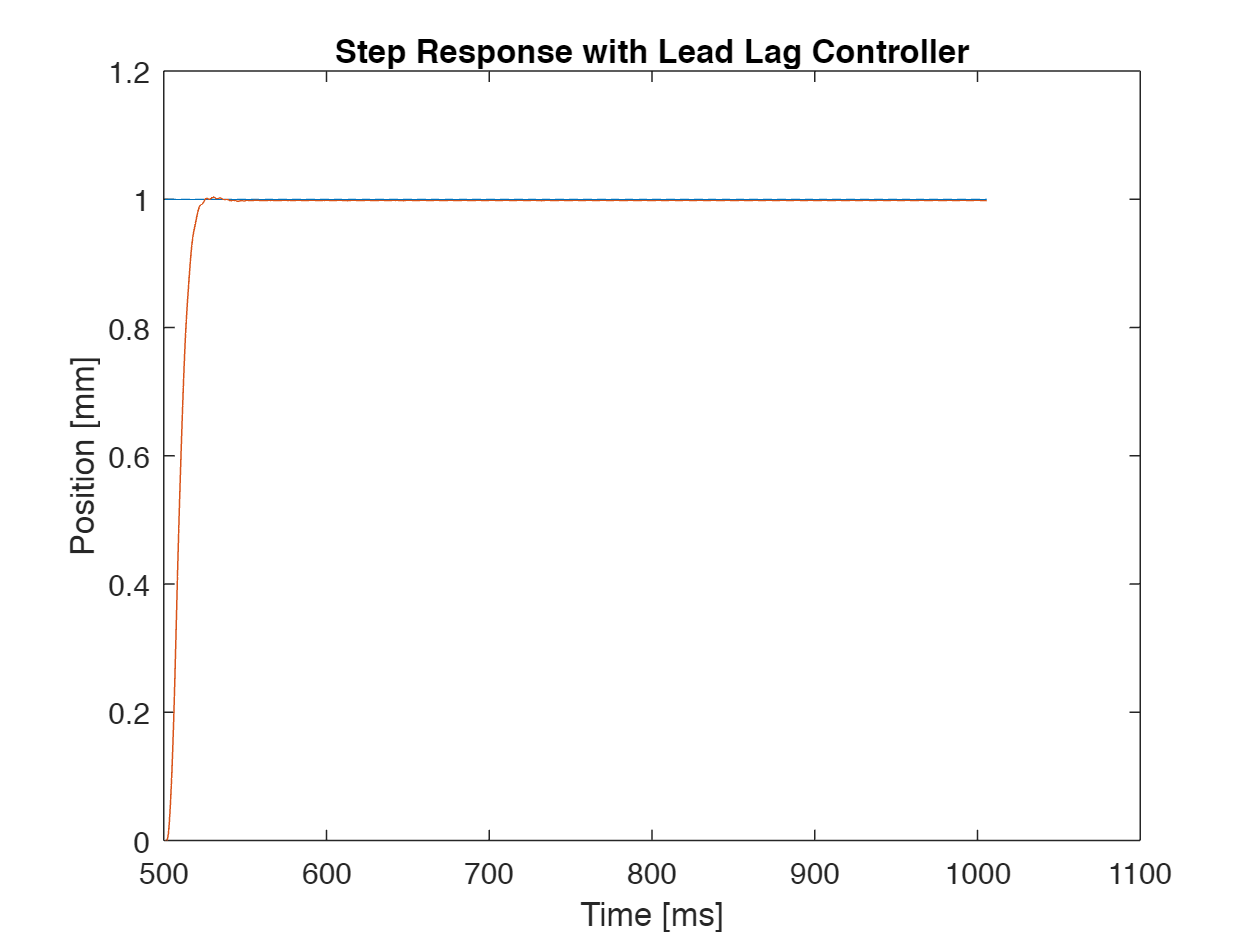

%experimental data LL compensator
time_start_step=.501/Ts;

data_LL_step=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\ll_s.csv", "NumHeaderLines",1);
time=data_LL_step.Var1(time_start_step:end);
reference_trajectory=data_LL_step.Var2(time_start_step:end);
position_mm=data_LL_step.Var3(time_start_step:end);

plot(time,reference_trajectory);
hold on;
plot(time,position_mm);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Step Response with Lead Lag Controller");
hold off;

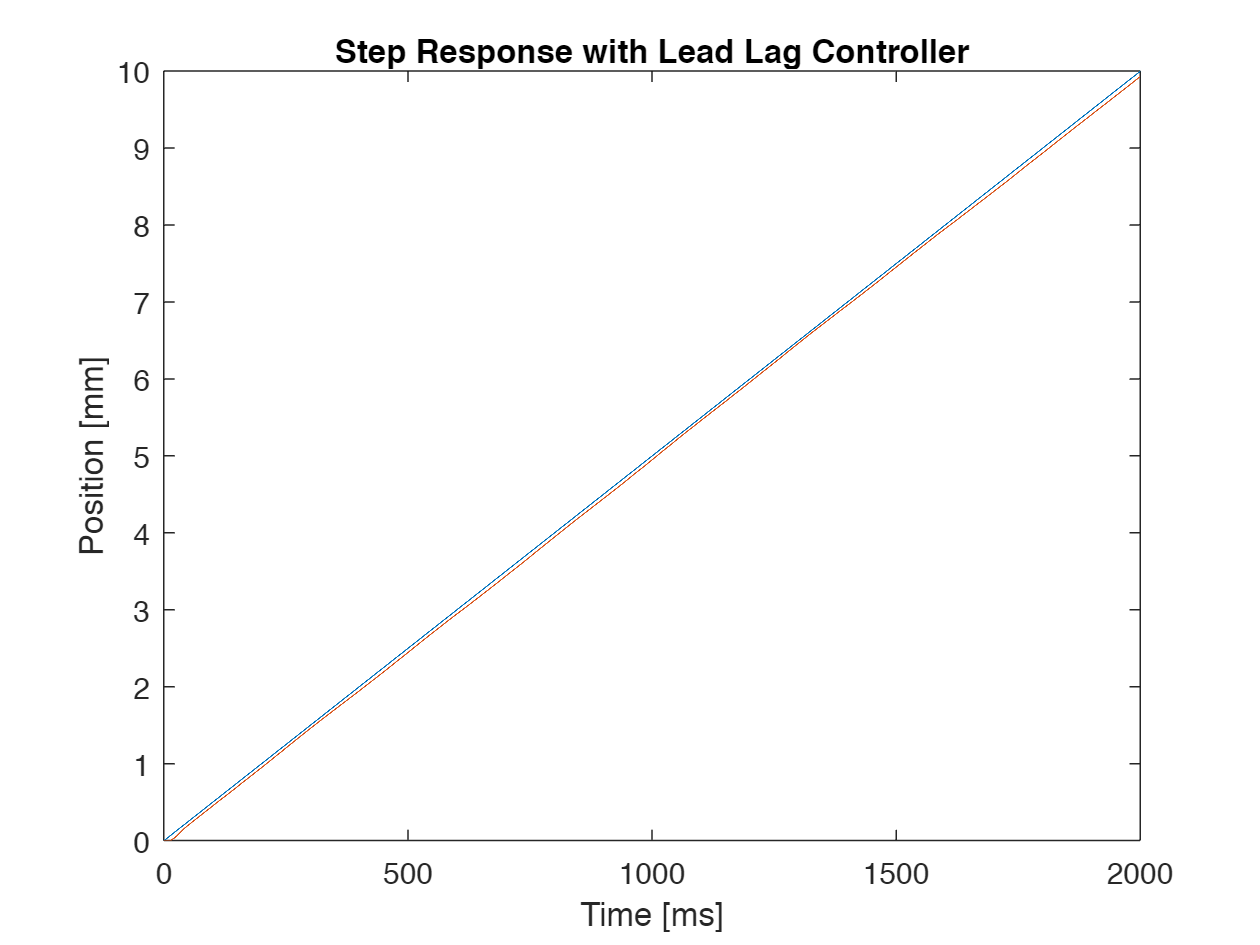


S_LL_exp=stepinfo(position_mm, time, 'RiseTimeLimits', RT); %0 to 63percent of 1
LL_rt_exp=S_LL_exp.RiseTime;
LL_overshoot_exp=(max(position_mm)-1);

%ll controller ramp
max_ramp_time=10000;
data_ll_ramp=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\ll_r.csv", "NumHeaderLines",1);
time=data_ll_ramp.Var1(1:max_ramp_time);
reference_trajectory=data_ll_ramp.Var2(1:max_ramp_time);
position_mm_ll=data_ll_ramp.Var3(1:max_ramp_time);

plot(time,reference_trajectory);
hold on;
plot(time,position_mm_ll);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Step Response with Lead Lag Controller");
LL_sserror_exp=(position_mm_ll(end-1)-10);
hold off;

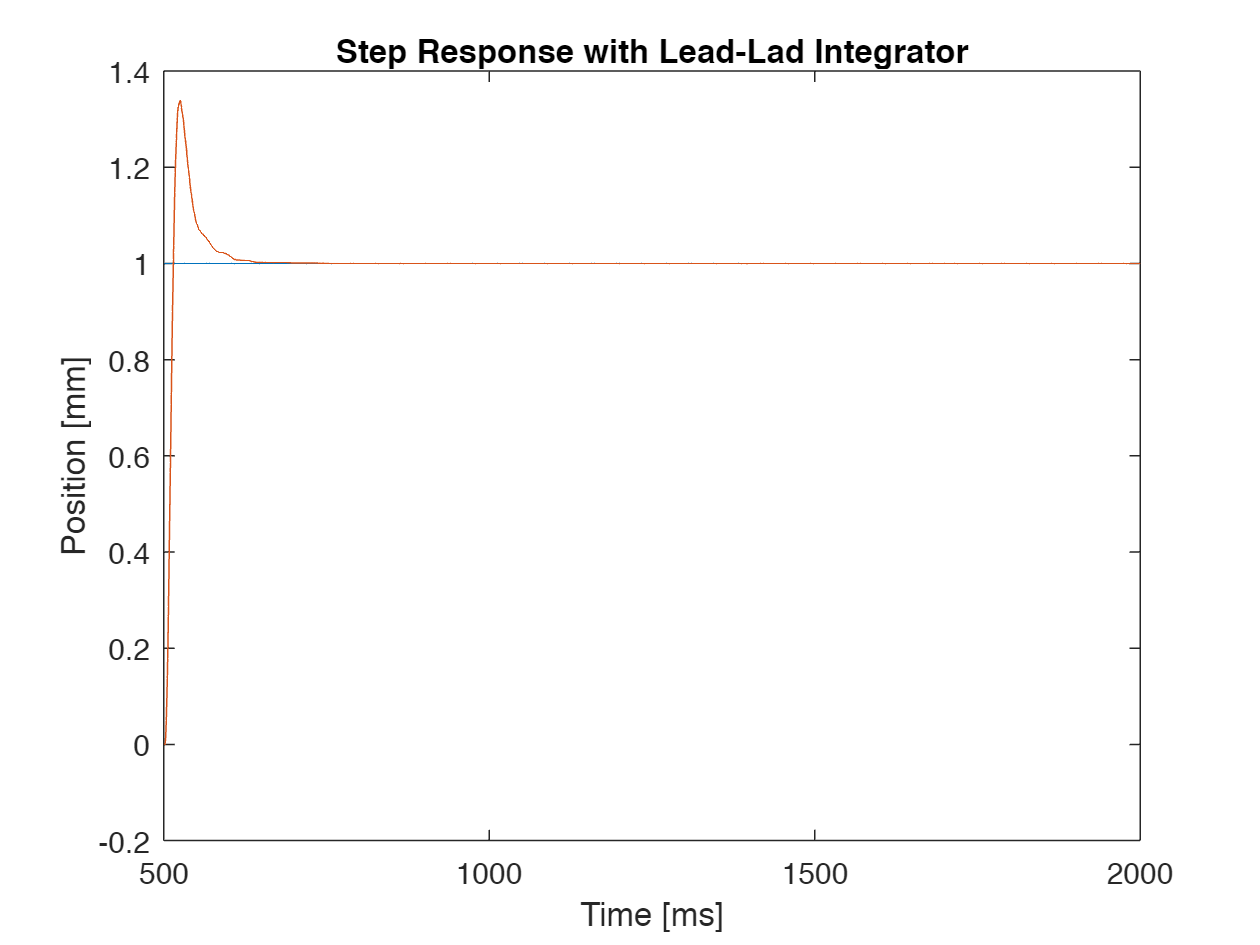

%experimental data LLI Controller
max_step_time=10000;
time_start_step=.501/Ts;

data_lli_step=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\lli_s.csv", "NumHeaderLines",1);
time=data_lli_step.Var1(time_start_step:max_step_time);
reference_trajectory=data_lli_step.Var2(time_start_step:max_step_time);
position_mm=data_lli_step.Var3(time_start_step:max_step_time);

plot(time,reference_trajectory);
hold on;
plot(time,position_mm);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Step Response with Lead-Lad Integrator");
hold off;

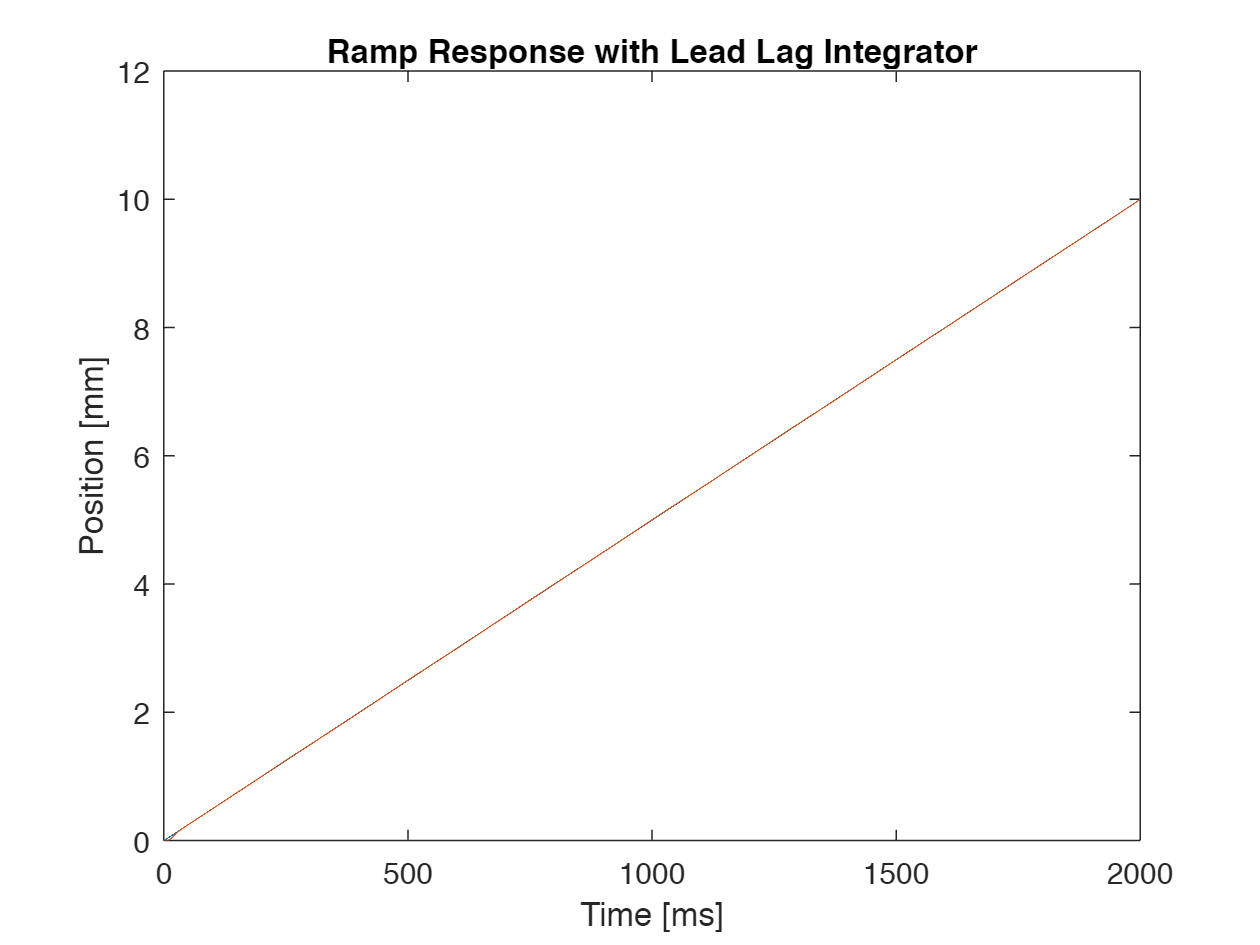



S_lli_exp=stepinfo(position_mm, time, 'RiseTimeLimits', RT); %0 to 63percent of 1
lli_rt_exp=S_lli_exp.RiseTime;
lli_overshoot_exp=(max(position_mm)-1);

%lli controller ramp
data_lli_ramp=readtable("C:\Users\Lachlan Reynolds\Desktop\Lachlan\lli_r.csv", "NumHeaderLines",1);
time=data_lli_ramp.Var1(1:max_ramp_time);
reference_trajectory=data_lli_ramp.Var2(1:max_ramp_time);
position_mm_lli=data_lli_ramp.Var3(1:max_ramp_time);

plot(time,reference_trajectory);
hold on;
plot(time,position_mm_lli);
xlabel("Time [ms]");
ylabel("Position [mm]");
title("Ramp Response with Lead Lag Integrator");
lli_sserror_exp=(position_mm_lli(end-1)-10);
hold off;

% results

%overshoot
k_overshoot_sim

k_overshoot_sim =     0.5781    0.3527    0.1272


k_overshoot_exp

k_overshoot_exp = 0.1964


%rise time
k_rt_sim

k_rt_sim =     0.0217    0.0265    0.0295


k_rt_exp

k_rt_exp = NaN


%ramp ss error
k_sserror_sim

k_sserror_sim =    -0.1365   -0.2754   -0.3908


k_sserror_exp

k_sserror_exp = -0.2586


%overshoot
LL_overshoot_sim

LL_overshoot_sim =          0         0    0.1699


LL_overshoot_exp

LL_overshoot_exp = 0.0035


%rise time
LL_rt_sim

LL_rt_sim =          0         0    0.0026


LL_rt_exp

LL_rt_exp = NaN


%ramp ss error
LL_sserror_sim

LL_sserror_sim = -0.0353

LL_sserror_exp

LL_sserror_exp = -0.0720


%overshoot
LLI_overshoot_sim

LLI_overshoot_sim = 1.2574

lli_overshoot_exp

lli_overshoot_exp = 0.3389


%rise time
LLI_rt_sim

LLI_rt_sim = 1.0000

lli_rt_exp

lli_rt_exp = 9.0558


%ramp ss error
LLI_sserror_sim

LLI_sserror_sim = -5.2489e-10

lli_sserror_exp

lli_sserror_exp = -7.0000e-04

toc

Elapsed time is 100.245543 seconds.
